# Using EstimateHRF_inAtlas

Estimate HRF in a convenient matlab structure for individual scan runs and group-level analysis. The below takes you through the process step-by-step.

by Michael Sun, Ph.D.

## Step 1a: Housekeeping: File Locations

`_________________________________________________________________________`

First we need to locate our fmri 4D files from our study

% Navigate to the correct directory
if ismac()      % I usually have the cluster smb mounted on a Mac like this
    root = '/Volumes/CANlab';
    cd('/Volumes/WASABI/derivatives/fmriprep')
elseif ispc()   % Otherwise on a PC or Linux box, it looks something like this
    % root = 'H:\Dropbox (Dartmouth College)\Tor Pinel datasets\Pinel_localizer\results\Brainomics_contrast_objects'
    root = '\\dartfs-hpc\rc\lab\C\CANlab\';
    cd('\\dartfs-hpc\rc\lab\C\CANlab\labdata\data\WASABI\derivatives\fmriprep')
else
    root = '/dartfs-hpc/rc/lab/C/CANlab/';
    cd('/dartfs-hpc/rc/lab/C/CANlab/labdata/data/WASABI/derivatives/fmriprep')
end
fmriprep_dir=pwd

fmriprep_dir = '/dartfs-hpc/rc/lab/C/CANlab/labdata/data/WASABI/derivatives/fmriprep'

## Step 1b: Housekeeping: Checking Dependencies

`_________________________________________________________________________`

Then we need to check if the Matlab **Signal Processing Toolbox, SPM, **and the **CANLab Core Tools **are installed. If not, use addpath() to add them to your Matlab path e.g., **addpath(genpath(YOUR_PATH_TO_CANLAB_CORE));**

% Check if Signal Processing Toolbox is installed
if license('test', 'Signal_Toolbox')
    fprintf('Signal Processing Toolbox is installed.\n');
else
    fprintf('Signal Processing Toolbox is not installed.\n');
end

Signal Processing Toolbox is installed.



% Optionally, you can also get the version information if it's installed
toolboxInfo = ver;
toolboxNames = {toolboxInfo.Name};
if any(strcmp(toolboxNames, 'Signal Processing Toolbox'))
    idx = find(strcmp(toolboxNames, 'Signal Processing Toolbox'));
    toolboxVersion = toolboxInfo(idx).Version;
    fprintf('Signal Processing Toolbox version: %s\n', toolboxVersion);
end

Signal Processing Toolbox version: 9.2



% Check if SPM is installed
if exist('spm', 'file') == 2
    fprintf('SPM is installed.\n');
else
    fprintf('SPM is not installed.\n');
end

SPM is installed.



% Check if CanlabCore Tools are installed
toolboxName = 'CANLab Core'; % Replace with the actual toolbox name
functionName = 'fmri_data'; % Replace with a function or file name from the toolbox

% Check if the function or file associated with the toolbox exists
if exist(functionName, 'file') == 2
    fprintf('%s is installed.\n', toolboxName);
else
    fprintf('%s is not installed.\n', toolboxName);
end

CANLab Core is installed.


You should have these in your path, otherwise you'll run into trouble down the line:

- SPM12

- CanlabCore Object-Oriented Tools

- Canlab Second_level_analysis_template_scripts

- Canlab Masks_Private

- Neuroimaging_Pattern_Masks

### If CANLab Core is installed correctly, you should be able to run this line:

subjects=canlab_list_subjects(fmriprep_dir, 'sub-*');
condition_names={'*heat_start','*warm_start','*imagine_cue','*imagine_start'};

## Step 2: Pick your raw 4D fMRI file, and their associated onsets and durations

`_________________________________________________________________________`

- Best use a 4D file that's minimally preprocessed like an fmriprep ***desc-preproc_bold.nii** file

- If you used SPM-style CANlab first-level modelling, its as easy as grabbing the relevant .mat files for the scan.

% Gather all the relevant files
file=dir(fullfile(fmriprep_dir, subjects{1}, 'ses-*', 'func','*bodymap*MNI152NLin2009cAsym*preproc_bold.nii.gz'));
a=fullfile({file.folder}',{file.name}');

% Select one file for processing
filenum=2;
fname=a{filenum};
f=fmri_data(fname);

Using default mask: /dartfs-hpc/rc/lab/C/CANlab/labdata/projects/WASABI/software/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 463243680 bytes
Loading image number: 

sub=strcat('sub-',extractBetween(fname, 'sub-', filesep));
ses=strcat('ses-',extractBetween(fname, 'ses-', filesep));
run=strcat('run-',extractBetween(fname, 'run-', '_'));

% Gather all relevant first-level files to get onset and duration times.
firstlvl_path=fileparts(strrep(fname, 'fmriprep', 'canlab_firstlvl'));

run_without_zeros = strrep(run, 'run-0', 'run-');
% Initialize run_values with both variants
run_values = {run{1}, run_without_zeros{1}};

% Initialize a flag to indicate if the directory was found
directory_found = false;

% Loop through the run values
for i = 1:numel(run_values)
    % Replace 'func' with the current run value
    current_run = run_values{i};
    current_firstlvl_path = fullfile(firstlvl_path, current_run);
    
    % Use dir to list directories matching the pattern
    firstlvl_dir = dir(fullfile(current_firstlvl_path, '*firstlvl'));
    
    % Check if the directory exists
    if ~isempty(firstlvl_dir)
        % Directory found, set the flag and break out of the loop
        directory_found = true;
        break;
    end
end

% Use the directory found, if any
if directory_found
    % Process the found directory here
    disp(['Directory found for ' current_run]);
    firstlvl_dir = dir(fullfile(current_firstlvl_path, '*firstlvl'));
else
    % Handle the case when neither directory was found
    disp('No directory found for either run-0X or run-X');
end

Directory found for run-02



firstlvl_files=dir(fullfile(firstlvl_dir.folder, firstlvl_dir.name));

% firstlvl_hot;
% Get Onset and Duration
% You will have to convert all your timings from seconds to TRs

TR=0.46;
for c = 1:numel(condition_names)
    full_path_pattern = fullfile(firstlvl_dir.folder, firstlvl_dir.name, [condition_names{c},'.mat']);
    c_files=dir(full_path_pattern);
    ons_dur(c)=load(fullfile(c_files.folder, c_files.name));
    
    ons(c)={round(ons_dur(c).onset{1}./TR)};
    dur(c)={round(ons_dur(c).duration{1}./TR)};
end

% Get R (noise) Matrix
full_path_pattern = fullfile(firstlvl_dir.folder, firstlvl_dir.name, 'noise_model.mat');
r_files=dir(full_path_pattern);
load(fullfile(r_files.folder, r_files.name));

## Step 2: Set your parameters for preprocessing and HRF fitting

`_________________________________________________________________________`

EstimateHRF_inAtlas takes 5 arguments: **fmri_data**, **PREPROC_PARAMS**, **HRF_PARAMS**, **atlas**, **ROIs**, and **outfile** filename.

- fmri_data object of your 4D fmri file

- **PREPROC_PARAMS** structure: stores all parameters for preprocessing your 4D file.

- **HRF_PARAMS** structure: stores all parameters for HRF estimation. Condition is a vertical vector of onsets that is fed into **hrf_fit_one_voxel()** you want to model. We can use the helper function **generateConditionTS()** to create this for us. 

Condition=generateConditionTS(f, condition_names, ons, dur);

Next, we'll fill in everything else:

PREPROC_PARAMS.TR=0.46;   % TR in seconds
PREPROC_PARAMS.smooth=6;  % 6mm FWHM smoothing kernel
PREPROC_PARAMS.R=R;          % Noise matrix  
PREPROC_PARAMS.hpf=0.18;   % High-pass Filter

HRF_PARAMS.Condition=Condition;
HRF_PARAMS.CondNames=condition_names;
HRF_PARAMS.TR=0.46;     % TR in seconds
HRF_PARAMS.T=22;        % Time Window that you want estimated in seconds
HRF_PARAMS.T=[26 26 4 22];        % WITH NEW multi-Time Window feature by Heejung

HRF_PARAMS.FWHM=6;      % 6mm FWHM smoothing kernel
HRF_PARAMS.alpha=0.001; % alpha level
HRF_PARAMS.types={'FIR','CHRF'}; % Choices are 'FIR', 'IL', and 'CHRF', but 'IL' often gets stuck so I don't include it here.

## Step 3: Set your Atlas and ROIs

`_________________________________________________________________________`

Pick the masks that you want to estimate HRFs for using:

- an **atlas** object

- a cell array of cellstrings with labels matching atlas**.labels** field

% at=load_atlas('canlab2023_fine_fmriprep20_1mm'); % In this example we use the CANlab 2018 2mm atlas
at=load_atlas('canlab2018_2mm'); % In this example we use the CANlab 2018 2mm atlas

Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat


% rois={'Ctx_4_L', 'Ctx_4_Ra_1', 'Ctx_V1_L', 'Ctx_V1_R'}; % Picked an arbitrary 4 labels in the atlas
rois=at.labels; % Or you can do this. Warning: This runs all regions in the atlas.

## Step 4: Set your output filepath

`_________________________________________________________________________`

Pick a cellstring that reflects the filepath and filename you want to save your results for. Leave off the file extension, as EstHRF_inAtlas will save out a filename with the **.mat** extension.

outfile=strrep(fname, '_bold.nii.gz', '_bold-HRF');
outfile=strrep(outfile, 'fmriprep', 'estHRF');
outfile=strrep(outfile, ['func', filesep], '')

## Step 5: Run the code

`_________________________________________________________________________`

Now run the code. You will get: 

- **timecourse:** A cell-array of timecourse vectors for every estimated HRF fit-type x region.

- **HRF:** An HRF structure object with descriptive information and summary statistics to be passed on to second-level analysis

- Nifti objects will be written out in your current working directory for the timeseries of each fit-type x voxel x condition so that you can re-mask them for new regions, saving you time.

% Run your time-series analysis on your 4-D fmri file. Note: Requires the Matlab Signal Processing Toolbox
tic
[timecourse, HRF]=EstimateHRF_inAtlas(f, PREPROC_PARAMS, HRF_PARAMS, at, rois, outfile);

Canlab_connectivity_preproc: starting preprocessing ... 
::: temporal filtering brain data... 
Done: data preprocessing in 2.5e+00 sec.

-------------------------------------------------------------1160Smoothed images with   6 FWHM filter
HRF estimation
HRF estimation
matrix_eval_function.m
_______________________________
Evaluating this function on 99837 variables:
    @(tc)hrf_fit_one_voxel_meval(tc,TR,Runc,T,method,mode)
...using this command:
[varargout{1}(i,:),varargout{2}(i,:),varargout{3}(i,:),varargout{4}(i,:),varargout{5}(i,:),varargout{6}(i,:),varargout{7}(i,:),varargout{8}(i,:)] = fhandle(double(Y(:,i)));
_______________________________
matrix_eval_function.m
_______________________________
Evaluating this function on 99837 variables:
    @(tc)hrf_fit_one_voxel_meval(tc,TR,Runc,T,method,mode)
...using this command:
[varargout{1}(i,:),varargout{2}(i,:),varargout{3}(i,:),varargout{4}(i,:),varargout{5}(i,:),varargo

toc

Elapsed time is 1709.987733 seconds.


## Step 6: Describe and/or Visualize Results

`_________________________________________________________________________`

You can now generate summary text from your HRF structure object.

describeHRF(HRF);

The FIR fitted Ctx_V1_L features 9 phases of activity for the x_heat_start condition
Phase 1, spanning TRs 1  5 features 1 peak(s), (at TR(s) 3 and features an AUC of 3.936 (voxel-normed: 0.0020071).
Phase 2, spanning TRs 6  12 features 1 trough(s), (at TR(s) 10 and features an AUC of 3.4716 (voxel-normed: 0.0017703).
Phase 3, spanning TRs 13  17 features 1 peak(s), (at TR(s) 14 and features an AUC of 2.0001 (voxel-normed: 0.0010199).
Phase 4, spanning TRs 18  23 features 1 trough(s), (at TR(s) 21 and features an AUC of 1.3851 (voxel-normed: 0.00070633).
Phase 5, spanning TRs 24  26 features 1 peak(s), (at TR(s) 25 and features an AUC of 1.2155 (voxel-normed: 0.00061983).
Phase 6, spanning TRs 27  31 features 1 trough(s), (at TR(s) 29 and features an AUC of 3.0853 (voxel-normed: 0.0015733).
Phase 7, spanning TRs 32  35 features 1 peak(s), (at TR(s) 33 and features an AUC of 1.4782 (voxel-normed: 0.00075378).
Phase 8, spanning TRs 43  46 features 1 trough(s), (at TR(s) 45 and features a

You can also generate a table of summary statistics from your HRF structure object.

T=generateHRFTable(HRF);

      Type              Region                  Condition         PhaseNum    PhaseSpan    Peaks    Troughs     TimeToPeak             AUC               AUC_VoxNormed    
    ________    _______________________    ___________________    ________    _________    _____    _______    ____________    ___________________    ____________________
    {'FIR' }    {'Ctx_V1_L'           }    {'x_heat_start'   }        1        1     5       1         0       {[       3]}       3.93600019260617     0.00200713931290473
    {'FIR' }    {'Ctx_V1_L'           }    {'x_heat_start'   }        2        6    12       0         1       {[      10]}       3.47157643177281 

Finally, you can generate plots for any region label in your atlas

Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat


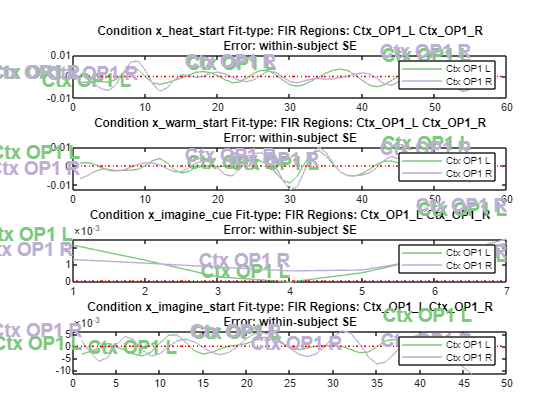

plotHRF(HRF, 'FIR', {'Ctx_OP1_L', 'Ctx_OP1_R'}); % Plot S2, to pick up on some burn signals.

## Step 7: Run for your Entire Study

`_________________________________________________________________________`

To run EstimateHRF_inAtlas for an entire study, you will need to merge a table of all of your 4D files with the onset and duration information that is found in your first-level directories. Here's how I might do it:

### a. First generate a 4-D file infoTable

% Define the file pattern to match preprocessed bold files
filePattern = fullfile(fmriprep_dir, 'sub-*', 'ses-*', 'func', '*MNI152NLin2009cAsym*preproc_bold.nii.gz');

% List all matching files
preprocFiles = dir(filePattern);

% Initialize empty arrays to store subject, session, and run information
subjects = {};
sessions = {};
runs = {};
scanfile = {};

% Loop through the preprocessed bold files
for i = 1:length(preprocFiles)
    % Parse subject, session, and run information from the file path
    filePath = fullfile(preprocFiles(i).folder, preprocFiles(i).name);
    parts = strsplit(filePath, filesep);
    
    % Initialize subject, session, and run variables
    subject = '';
    session = '';
    run = '';
    
    % Find the cells that contain 'sub', 'ses', and 'func'
    subIdx = find(contains(parts, 'sub'));
    sesIdx = find(contains(parts, 'ses'));
    runIdx = find(contains(parts, 'run'));
    
    % Extract subject, session, and run labels if found
    if any(~isempty(subIdx) & subIdx <= numel(parts))
        subject = parts{subIdx};
    end
    if any(~isempty(sesIdx) & sesIdx <= numel(parts))
        session = parts{sesIdx};
    end
    if any(~isempty(runIdx) & runIdx <= numel(parts))
        run = char(strcat('run-', extractBetween(parts{runIdx}, 'run-', '_')));
    end
    
    % Append information to arrays
    subjects{end+1} = subject;
    sessions{end+1} = session;
    runs{end+1} = run;
    scanfile{end+1} = parts{end};
end

% Create a table with the extracted information
infoTable = table(subjects', sessions', runs', scanfile', 'VariableNames', {'Subject', 'Session', 'Run', 'ScanFile'});

% Display the table
disp(infoTable);

         Subject          Session         Run                                                              ScanFile                                                       
    _________________    __________    __________    _____________________________________________________________________________________________________________________

    {'sub-SID000002'}    {'ses-01'}    {'run-01'}    {'sub-SID000002_ses-01_task-movemap_acq-mb8_run-01_space-MNI152NLin2009cAsym_desc-preproc_bold.nii.gz'              }
    {'sub-SID000002'}    {'ses-01'}    {'run-02'}    {'sub-SID000002_ses-01_task-movemap_acq-mb8_run-02_space-MNI152NLin2009cAsym_desc-preproc_bold.nii.gz'              }
    {'sub-SID000002'}    {'ses-01'}    {'run-03'}    {'sub-SID000002_ses-01_task-movemap_acq-mb8_run-03_space-MNI152NLin2009cAsym_desc-preproc_bold.nii.gz'              }
    {'su

### b. Generate a table column of onsets and durations

% This takes 3-15 minutes.

% Gather all relevant first-level files to get onset and duration times.
firstlvl_path=fullfile(fileparts(fmriprep_dir), 'canlab_firstlvl');
tic
dict={};
for r =1:height(infoTable)
    run_without_zeros = strrep(char(infoTable{r, "Run"}), 'run-0', 'run-');
    % Initialize run_values with both variants
    run_values = {char(infoTable{r, "Run"}), run_without_zeros};
    % Initialize a flag to indicate if the directory was found
    directory_found = false;

    % Loop through the run values
    for i = 1:numel(run_values)
        current_run = run_values{i};
        current_firstlvl_path = fullfile(firstlvl_path, char(infoTable{r, "Subject"}), char(infoTable{r, "Session"}), 'func', current_run);
        
        % Use dir to list directories matching the pattern
        firstlvl_dir = dir(fullfile(current_firstlvl_path, '*firstlvl'));
        
        % Check if the directory exists
        if ~isempty(firstlvl_dir)
            % Directory found, set the flag and break out of the loop
            directory_found = true;
            break;
        end
    end

    if directory_found==true;
        % mats=dir(fullfile(firstlvl_path, char(infoTable{r, "Subject"}), char(infoTable{r, "Session"}), char(infoTable{r, "Run"}), '*_firstlvl', '*.mat'))
        mats=dir(fullfile(firstlvl_dir.folder, firstlvl_dir.name, '*.mat'));
        % For each .mat, strip the name of .mat and generate a column if it doesn't exist 
        for i = 1:length(mats)
            % Extract the filename without the .mat extension
            filename = mats(i).name;
            [~, name, ~] = fileparts(filename);
            
            % Step 3: Check if the column exists in infoTable
            if ~ismember(name, infoTable.Properties.VariableNames)
                % Step 4: If the column doesn't exist, add it with empty values
                % Create an empty cell for each row in the new column
                infoTable.(name) = cell(size(infoTable, 1), 1);
            end
            
            data=load(fullfile(mats(i).folder, mats(i).name));
            
            % Check if 'onset' and 'duration' exist, and if not, check for 'R'
            if isfield(data, 'onset') && isfield(data, 'duration')
                TR=0.46;
                try
                    onset = {round(data.onset{1}./TR)};
                    duration = {round(data.duration{1}./TR)};
                    % Create a dictionary to hold 'onset' and 'duration'
                    infoTable.(name){r} = containers.Map({'onset', 'duration'}, {onset, duration});
                catch
                    warning([fullfile(mats(i).folder, mats(i).name), ' onset and duration in invalid format.'])
                end
    
            elseif isfield(data, 'R')
                % If 'onset' and 'duration' don't exist, but 'R' does, use 'R'
                R = data.R;
                infoTable.(name){r} = R;
            else
                % Handle the case where neither 'onset' and 'duration' nor 'R' exist
                onset = [];
                duration = [];
                R=[];
                infoTable.(name){r}=[];
            end
            
        end
    end
end
toc

Elapsed time is 197.377749 seconds.


### c. Now merge the two to create a JOB table and save it somewhere:

PREPROC_PARAMS=struct;
PREPROC_PARAMS.TR=0.46;   % TR in seconds
PREPROC_PARAMS.hpf=0.018; % 180hz
PREPROC_PARAMS.smooth=6;  % 6mm FWHM smoothing kernel

HRF_PARAMS=struct;
HRF_PARAMS.TR=0.46;             % TR in seconds
HRF_PARAMS.T=[26 26 4 22];      % Time Window that you want estimated in seconds
HRF_PARAMS.FWHM=6;              % 6mm FWHM smoothing kernel
HRF_PARAMS.alpha=0.001;         % alpha level
HRF_PARAMS.types={'FIR','CHRF'}; % Choices are 'FIR', 'IL', and 'CHRF', but 'IL' often gets stuck so I don't include it here.

tic
% Assuming 'infoTable' is your existing table

% Create a logical index to filter rows containing 'task-bodymap*'
logicalIndex = contains(infoTable.ScanFile, 'task-bodymap');

% Use the logical index to subset the table
bodymapInfoTable = infoTable(logicalIndex, :);

% 'subsetInfoTable' now contains only rows where 'ScanFile' contains 'task-bodymap*'

% Initialize cell arrays to store onset and duration
ons = cell(size(bodymapInfoTable, 1), 1);
dur = cell(size(bodymapInfoTable, 1), 1);

% Define the target strings in the desired order
targetStrings = {'heat_start', 'warm_start', 'imagine_cue', 'imagine_start'};
condition_names=targetStrings;

Condition={};
% Loop through the rows
% Initialize cell arrays to store onset and duration for the current row
onsRow = {};
durRow = {};
for row = 1:size(bodymapInfoTable, 1)
    onsRow{row} = [];
    durRow{row} = [];
    
    % Loop through the target strings in the desired order
    for c = 1:numel(condition_names)
        % Find the columns that contain the current target string
        % matchingCols = find(contains(bodymapInfoTable.Properties.VariableNames, condition_names{c}));
        matchingCols = find(endsWith(bodymapInfoTable.Properties.VariableNames, condition_names{c}));

        % Loop through the matching columns
        for col = matchingCols
            % Check if the cell in the current row and column is not empty
            if ~isempty(bodymapInfoTable{row, col}) % Add 4 to account for the first four columns
                % Extract the dictionary from the cell
                dict = bodymapInfoTable{row, col}{1}; % Add 4 to account for the first four columns
                
                % Check if it's a dictionary and contains 'onset' and 'duration' keys
                if isa(dict, 'containers.Map') && isKey(dict, 'onset') && isKey(dict, 'duration')
                    % Extract 'onset' and 'duration' values and store in onsRow and durRow
                    ons = dict('onset');
                    dur = dict('duration');

                    onsRow{row}{c} = ons{1};
                    durRow{row}{c} = dur{1};
                end
            end
        end

    end

    try
        bodymapInfoTable.Condition{row}=generateConditionTS(height(bodymapInfoTable.noise_model{row}), ...
            condition_names, onsRow{row}, durRow{row});
        % Store the onset and duration cell arrays for the current row in ons and dur
        bodymapInfoTable.ons{row} = onsRow{row};
        bodymapInfoTable.dur{row} = durRow{row};

        PREPROC_PARAMS=struct();
        PREPROC_PARAMS.TR=0.46;   % TR in seconds
        PREPROC_PARAMS.hpf=0.018; % 180hz                   
        PREPROC_PARAMS.R=bodymapInfoTable.noise_model{row};
        PREPROC_PARAMS.smooth=6;  % 6mm FWHM smoothing kernel
        bodymapInfoTable.PREPROC_PARAMS{row}=PREPROC_PARAMS;

        HRF_PARAMS=struct();
        HRF_PARAMS.Condition=bodymapInfoTable.Condition{row};
        HRF_PARAMS.CondNames=condition_names;
        HRF_PARAMS.TR=0.46;     % TR in seconds
        HRF_PARAMS.T=[26 26 4 22];        % Time Window that you want estimated in seconds
        HRF_PARAMS.FWHM=6;      % 6mm FWHM smoothing kernel
        HRF_PARAMS.alpha=0.001; % alpha level
        HRF_PARAMS.types={'FIR','CHRF'}; % Choices are 'FIR', 'IL', and 'CHRF', but 'IL' often gets stuck so I don't include it here.
        bodymapInfoTable.HRF_PARAMS{row}=HRF_PARAMS;

        bodymapInfoTable.outfile{row}=strrep(fullfile(fileparts(fmriprep_dir), 'estHRF', bodymapInfoTable.Subject{row}, bodymapInfoTable.Session{row}, '', strrep(bodymapInfoTable.ScanFile{row}, '.nii.gz', '')), '\', '/');
    catch
        warning(['Error generating job columns for row ', [num2str(row), ' '], bodymapInfoTable.ScanFile{row}]);
    end
end

## Bodymap Job Table

tic
bodymapInfoTable=processJobTable(infoTable, 'task-bodymap', {'heat_start', 'warm_start', 'imagine_cue', 'imagine_start'}, HRF_PARAMS, PREPROC_PARAMS);

toc

Elapsed time is 6.639961 seconds.


## Movemap Job Table

tic
movemapInfoTable=processJobTable(infoTable, 'task-movemap', {'move', 'cue'}, HRF_PARAMS, PREPROC_PARAMS);
toc

Elapsed time is 1.178184 seconds.


## Acceptmap Job Table

tic
acceptmapInfoTable=processJobTable(infoTable, 'task-acceptmap', {'heat_start', 'rating_start'}, HRF_PARAMS, PREPROC_PARAMS);

toc

Elapsed time is 0.668419 seconds.


## Distractmap Job Table

tic
distractmapInfoTable=processJobTable(infoTable, 'task-distractmap', {'_stimBlock', '_stimblock', 'rest_stim', '_nostimblock', '_stim'}, HRF_PARAMS, PREPROC_PARAMS);

toc

Elapsed time is 0.760382 seconds.


## PinelLocalizer Job Table

tic
pinelInfoTable=processJobTable(infoTable, 'task-pinel', {'Click', 'Lang', 'Comp', 'Checker'}, HRF_PARAMS, PREPROC_PARAMS);
toc

Elapsed time is 0.821306 seconds.


### d. Prototype your code so that you don't get any errors when you attempt to parallelize it down the line

load('//dartfs-hpc/rc/lab/C/CANlab/labdata/projects/WASABI/WASABI_N_of_Few/analysis/infoTable.mat', 'bodymapInfoTable');
disp('bodymapInfoTable successfully loaded.')

% Get the current row index from the SLURM array task ID
fmriprep_dir='//dartfs-hpc/rc/lab/C/CANlab/labdata/data/WASABI/derivatives/fmriprep-try2';
% row = str2double(getenv('SLURM_ARRAY_TASK_ID'));
row=1;
at=load_atlas('canlab2018_2mm');
rois=at.labels();

[timecourse, HRF] = EstimateHRF_inAtlas(fmri_data(fullfile(fmriprep_dir, bodymapInfoTable.Subject{row}, bodymapInfoTable.Session{row}, 'func', bodymapInfoTable.ScanFile{row})), bodymapInfoTable.PREPROC_PARAMS{row}, bodymapInfoTable.HRF_PARAMS{row}, at, rois, bodymapInfoTable.outfile{row})

### e. Finally, create a slurm job for your study:

% Run this in bash/sbatch, not in Matlab.
% #!/bin/bash
% #SBATCH --job-name=estHRF
% #SBATCH --output=estHRF_log/estHRF_%A_%a.out
% #SBATCH --error=estHRF_log/estHRF_%A_%a.err
% #SBATCH --nodes=1
% #SBATCH --cpus-per-task=4
% #SBATCH --mem-per-cpu=4GB
% #SBATCH --array=1-487  # Replace 487 with the total number of rows
% #SBATCH --account=DBIC
% #SBATCH --time=3-01:00:00
% 
% 
% mkdir -p estHRF_log
% 
% # Load MATLAB module
% module load matlab/r2022a
% 
% # Define your MATLAB code here
% matlab -nodisplay -nosplash << EOF
% addpath(genpath('//dartfs-hpc/rc/lab/C/CANlab/modules/spm12'));
% addpath(genpath('//dartfs-hpc/rc/lab/C/CANlab/labdata/projects/WASABI/software'));
% load('//dartfs-hpc/rc/lab/C/CANlab/labdata/projects/WASABI/WASABI_N_of_Few/analysis/infoTable.mat', 'bodymapInfoTable');
% disp('bodymapInfoTable successfully loaded.')
% 
% % Get the current row index from the SLURM array task ID
% fmriprep_dir='//dartfs-hpc/rc/lab/C/CANlab/labdata/data/WASABI/derivatives/fmriprep-try2';
% row = str2double(getenv('SLURM_ARRAY_TASK_ID'));
% row=1
% 
% % Choose your atlas
% % at=load_atlas('canlab2018_2mm');
% load('//dartfs-hpc/rc/lab/C/CANlab/labdata/projects/WASABI/WASABI_N_of_Few/analysis/WASABI-NofFew_BodyMap/masks/nps_atlases.mat');
% at=merge_atlases(npspos, npsneg);
% rois=at.labels();
% 
% % Display run information
% disp(bodymapInfoTable.ScanFile{row});
% disp('canlab2018_2mm');
% disp('All ROIs');
% 
% % Your MATLAB code here, replacing 'row' with '$row' to access the current array task
% [timecourse, HRF] = EstimateHRF_inAtlas(fmri_data(fullfile(fmriprep_dir, bodymapInfoTable.Subject{row}, bodymapInfoTable.Session{row}, 'func', bodymapInfoTable.ScanFile{row})), bodymapInfoTable.PREPROC_PARAMS{row}, bodymapInfoTable.HRF_PARAMS{row}, at, rois, bodymapInfoTable.outfile{row})
% 
% exit
% EOF

## Step 8: Second-Level Analyses: Averaging Repeated Scans by Individual

`_________________________________________________________________________`

Here's how I might do it:

basedir='//dartfs-hpc/rc/lab/C/CANlab/labdata/data/WASABI/derivatives/estHRF_WASABIROIs';
cd(basedir);
% Load up all the .mat files you generated with estHRF_inAtlas for each subject
subjects=canlab_list_subjects(basedir, 'sub-*');
HRF_data = cell(1, length(subjects));
tc_data = cell(1, length(subjects));

WASABIROI_HRF = cell(1, length(subjects));
for s = 1:numel(subjects)
    WASABIROI_HRF{s}=dir(fullfile(basedir, subjects{s},'**', '*.mat'));

    % Initialize cell arrays to store the data
    HRF_data{s} = cell(1, length(WASABIROI_HRF{s}));
    tc_data{s} = cell(1, length(WASABIROI_HRF{s}));
    
    % Loop through each run file and load the data
    for r = 1:length(WASABIROI_HRF{s})
        fullpath = fullfile(WASABIROI_HRF{s}(r).folder, WASABIROI_HRF{s}(r).name);
        data = load(fullpath);  % Load the .mat file
        
        % Assuming each .mat file contains variables named 'HRF' and 'tc'
        HRF_data{s}{r} = data.HRF;
        tc_data{s}{r} = data.tc;
    end
end

[WASABIROIs_HRF_2, HRF_data, tc_data_NPSpos]=process_HRF_dir('//dartfs-hpc/rc/lab/C/CANlab/labdata/data/WASABI/derivatives/estHRF_WASABIROIs', at);

% at=load_atlas('canlab2018_2mm')
load('//dartfs-hpc/rc/lab/C/CANlab/labdata/projects/WASABI/WASABI_N_of_Few/analysis/WASABI-NofFew_BodyMap/masks/WASABI_atlas.mat');
at=testatlas;

WASABIROIs_HRF = cell(1, length(subjects));

sub-SID000002


The FIR fitted ACC features 1 phases of activity for the hot condition
Phase 1, spanning TRs 1  46 features 2 peak(s), (at TR(s) 14  37 and features an AUC of 162.0722 (voxel-normed: 0.041536).
The FIR fitted BG features 4 phases of activity for the hot condition
Phase 1, spanning TRs 1  35 features 1 trough(s), (at TR(s) 4 and features an AUC of 31.635 (voxel-normed: 0.0055084).
Phase 2, spanning TRs 11  13 features 1 peak(s), (at TR(s) 12 and features an AUC of 1.9793 (voxel-normed: 0.00034465).
Phase 3, spanning TRs 17  19 features 1 peak(s), (at TR(s) 18 and features an AUC of 1.7067 (voxel-normed: 0.00029717).
Phase 4, spanning TRs 36  46 features 1 peak(s), (at TR(s) 44 and features an AUC of 4.2009 (voxel-normed: 0.00073148).
The FIR fitted DLPFC features 1 phases of activity for the hot condition
Phase 1, spanning TRs 1  46 features 1 peak(s), (at TR(s) 13 and features an AUC of 35.3075 (voxel-normed: 0.0045237).
The FIR fitted Insula features 1 phases of activity for the hot c

sub-SID000743


The FIR fitted ACC features 1 phases of activity for the hot condition
Phase 1, spanning TRs 1  46 features 2 peak(s), (at TR(s) 14  37 and features an AUC of 162.0722 (voxel-normed: 0.041536).
The FIR fitted BG features 4 phases of activity for the hot condition
Phase 1, spanning TRs 1  35 features 1 trough(s), (at TR(s) 4 and features an AUC of 31.635 (voxel-normed: 0.0055084).
Phase 2, spanning TRs 11  13 features 1 peak(s), (at TR(s) 12 and features an AUC of 1.9793 (voxel-normed: 0.00034465).
Phase 3, spanning TRs 17  19 features 1 peak(s), (at TR(s) 18 and features an AUC of 1.7067 (voxel-normed: 0.00029717).
Phase 4, spanning TRs 36  46 features 1 peak(s), (at TR(s) 44 and features an AUC of 4.2009 (voxel-normed: 0.00073148).
The FIR fitted DLPFC features 1 phases of activity for the hot condition
Phase 1, spanning TRs 1  46 features 1 peak(s), (at TR(s) 13 and features an AUC of 35.3075 (voxel-normed: 0.0045237).
The FIR fitted Insula features 1 phases of activity for the hot c

sub-SID001567


The FIR fitted ACC features 1 phases of activity for the hot condition
Phase 1, spanning TRs 1  46 features 2 peak(s), (at TR(s) 14  37 and features an AUC of 162.0722 (voxel-normed: 0.041536).
The FIR fitted BG features 4 phases of activity for the hot condition
Phase 1, spanning TRs 1  35 features 1 trough(s), (at TR(s) 4 and features an AUC of 31.635 (voxel-normed: 0.0055084).
Phase 2, spanning TRs 11  13 features 1 peak(s), (at TR(s) 12 and features an AUC of 1.9793 (voxel-normed: 0.00034465).
Phase 3, spanning TRs 17  19 features 1 peak(s), (at TR(s) 18 and features an AUC of 1.7067 (voxel-normed: 0.00029717).
Phase 4, spanning TRs 36  46 features 1 peak(s), (at TR(s) 44 and features an AUC of 4.2009 (voxel-normed: 0.00073148).
The FIR fitted DLPFC features 1 phases of activity for the hot condition
Phase 1, spanning TRs 1  46 features 1 peak(s), (at TR(s) 13 and features an AUC of 35.3075 (voxel-normed: 0.0045237).
The FIR fitted Insula features 1 phases of activity for the hot c

sub-SID001641


The FIR fitted ACC features 1 phases of activity for the hot condition
Phase 1, spanning TRs 1  46 features 2 peak(s), (at TR(s) 14  37 and features an AUC of 162.0722 (voxel-normed: 0.041536).
The FIR fitted BG features 4 phases of activity for the hot condition
Phase 1, spanning TRs 1  35 features 1 trough(s), (at TR(s) 4 and features an AUC of 31.635 (voxel-normed: 0.0055084).
Phase 2, spanning TRs 11  13 features 1 peak(s), (at TR(s) 12 and features an AUC of 1.9793 (voxel-normed: 0.00034465).
Phase 3, spanning TRs 17  19 features 1 peak(s), (at TR(s) 18 and features an AUC of 1.7067 (voxel-normed: 0.00029717).
Phase 4, spanning TRs 36  46 features 1 peak(s), (at TR(s) 44 and features an AUC of 4.2009 (voxel-normed: 0.00073148).
The FIR fitted DLPFC features 1 phases of activity for the hot condition
Phase 1, spanning TRs 1  46 features 1 peak(s), (at TR(s) 13 and features an AUC of 35.3075 (voxel-normed: 0.0045237).
The FIR fitted Insula features 1 phases of activity for the hot c

sub-SID001684


The FIR fitted ACC features 1 phases of activity for the hot condition
Phase 1, spanning TRs 1  46 features 2 peak(s), (at TR(s) 14  37 and features an AUC of 162.0722 (voxel-normed: 0.041536).
The FIR fitted BG features 4 phases of activity for the hot condition
Phase 1, spanning TRs 1  35 features 1 trough(s), (at TR(s) 4 and features an AUC of 31.635 (voxel-normed: 0.0055084).
Phase 2, spanning TRs 11  13 features 1 peak(s), (at TR(s) 12 and features an AUC of 1.9793 (voxel-normed: 0.00034465).
Phase 3, spanning TRs 17  19 features 1 peak(s), (at TR(s) 18 and features an AUC of 1.7067 (voxel-normed: 0.00029717).
Phase 4, spanning TRs 36  46 features 1 peak(s), (at TR(s) 44 and features an AUC of 4.2009 (voxel-normed: 0.00073148).
The FIR fitted DLPFC features 1 phases of activity for the hot condition
Phase 1, spanning TRs 1  46 features 1 peak(s), (at TR(s) 13 and features an AUC of 35.3075 (voxel-normed: 0.0045237).
The FIR fitted Insula features 1 phases of activity for the hot c

sub-SID001804


The FIR fitted ACC features 1 phases of activity for the hot condition
Phase 1, spanning TRs 1  46 features 2 peak(s), (at TR(s) 14  37 and features an AUC of 162.0722 (voxel-normed: 0.041536).
The FIR fitted BG features 4 phases of activity for the hot condition
Phase 1, spanning TRs 1  35 features 1 trough(s), (at TR(s) 4 and features an AUC of 31.635 (voxel-normed: 0.0055084).
Phase 2, spanning TRs 11  13 features 1 peak(s), (at TR(s) 12 and features an AUC of 1.9793 (voxel-normed: 0.00034465).
Phase 3, spanning TRs 17  19 features 1 peak(s), (at TR(s) 18 and features an AUC of 1.7067 (voxel-normed: 0.00029717).
Phase 4, spanning TRs 36  46 features 1 peak(s), (at TR(s) 44 and features an AUC of 4.2009 (voxel-normed: 0.00073148).
The FIR fitted DLPFC features 1 phases of activity for the hot condition
Phase 1, spanning TRs 1  46 features 1 peak(s), (at TR(s) 13 and features an AUC of 35.3075 (voxel-normed: 0.0045237).
The FIR fitted Insula features 1 phases of activity for the hot c

sub-SID001852


The FIR fitted ACC features 1 phases of activity for the hot condition
Phase 1, spanning TRs 1  46 features 2 peak(s), (at TR(s) 14  37 and features an AUC of 162.0722 (voxel-normed: 0.041536).
The FIR fitted BG features 4 phases of activity for the hot condition
Phase 1, spanning TRs 1  35 features 1 trough(s), (at TR(s) 4 and features an AUC of 31.635 (voxel-normed: 0.0055084).
Phase 2, spanning TRs 11  13 features 1 peak(s), (at TR(s) 12 and features an AUC of 1.9793 (voxel-normed: 0.00034465).
Phase 3, spanning TRs 17  19 features 1 peak(s), (at TR(s) 18 and features an AUC of 1.7067 (voxel-normed: 0.00029717).
Phase 4, spanning TRs 36  46 features 1 peak(s), (at TR(s) 44 and features an AUC of 4.2009 (voxel-normed: 0.00073148).
The FIR fitted DLPFC features 1 phases of activity for the hot condition
Phase 1, spanning TRs 1  46 features 1 peak(s), (at TR(s) 13 and features an AUC of 35.3075 (voxel-normed: 0.0045237).
The FIR fitted Insula features 1 phases of activity for the hot c

sub-SID001907


The FIR fitted ACC features 1 phases of activity for the hot condition
Phase 1, spanning TRs 1  46 features 2 peak(s), (at TR(s) 14  37 and features an AUC of 162.0722 (voxel-normed: 0.041536).
The FIR fitted BG features 4 phases of activity for the hot condition
Phase 1, spanning TRs 1  35 features 1 trough(s), (at TR(s) 4 and features an AUC of 31.635 (voxel-normed: 0.0055084).
Phase 2, spanning TRs 11  13 features 1 peak(s), (at TR(s) 12 and features an AUC of 1.9793 (voxel-normed: 0.00034465).
Phase 3, spanning TRs 17  19 features 1 peak(s), (at TR(s) 18 and features an AUC of 1.7067 (voxel-normed: 0.00029717).
Phase 4, spanning TRs 36  46 features 1 peak(s), (at TR(s) 44 and features an AUC of 4.2009 (voxel-normed: 0.00073148).
The FIR fitted DLPFC features 1 phases of activity for the hot condition
Phase 1, spanning TRs 1  46 features 1 peak(s), (at TR(s) 13 and features an AUC of 35.3075 (voxel-normed: 0.0045237).
The FIR fitted Insula features 1 phases of activity for the hot c

sub-SID002035


The FIR fitted ACC features 1 phases of activity for the hot condition
Phase 1, spanning TRs 1  46 features 2 peak(s), (at TR(s) 14  37 and features an AUC of 162.0722 (voxel-normed: 0.041536).
The FIR fitted BG features 4 phases of activity for the hot condition
Phase 1, spanning TRs 1  35 features 1 trough(s), (at TR(s) 4 and features an AUC of 31.635 (voxel-normed: 0.0055084).
Phase 2, spanning TRs 11  13 features 1 peak(s), (at TR(s) 12 and features an AUC of 1.9793 (voxel-normed: 0.00034465).
Phase 3, spanning TRs 17  19 features 1 peak(s), (at TR(s) 18 and features an AUC of 1.7067 (voxel-normed: 0.00029717).
Phase 4, spanning TRs 36  46 features 1 peak(s), (at TR(s) 44 and features an AUC of 4.2009 (voxel-normed: 0.00073148).
The FIR fitted DLPFC features 1 phases of activity for the hot condition
Phase 1, spanning TRs 1  46 features 1 peak(s), (at TR(s) 13 and features an AUC of 35.3075 (voxel-normed: 0.0045237).
The FIR fitted Insula features 1 phases of activity for the hot c

sub-SID002328


The FIR fitted ACC features 1 phases of activity for the hot condition
Phase 1, spanning TRs 1  46 features 2 peak(s), (at TR(s) 14  37 and features an AUC of 162.0722 (voxel-normed: 0.041536).
The FIR fitted BG features 4 phases of activity for the hot condition
Phase 1, spanning TRs 1  35 features 1 trough(s), (at TR(s) 4 and features an AUC of 31.635 (voxel-normed: 0.0055084).
Phase 2, spanning TRs 11  13 features 1 peak(s), (at TR(s) 12 and features an AUC of 1.9793 (voxel-normed: 0.00034465).
Phase 3, spanning TRs 17  19 features 1 peak(s), (at TR(s) 18 and features an AUC of 1.7067 (voxel-normed: 0.00029717).
Phase 4, spanning TRs 36  46 features 1 peak(s), (at TR(s) 44 and features an AUC of 4.2009 (voxel-normed: 0.00073148).
The FIR fitted DLPFC features 1 phases of activity for the hot condition
Phase 1, spanning TRs 1  46 features 1 peak(s), (at TR(s) 13 and features an AUC of 35.3075 (voxel-normed: 0.0045237).
The FIR fitted Insula features 1 phases of activity for the hot c

for s = 1:numel(subjects)
    WASABIROIs_HRF{s}=HRF_avg(HRF_data{s}, at);
end

sub-SID000002


      Type        Region       Condition     PhaseNum    PhaseSpan    Peaks    Troughs    TimeToPeak           AUC               AUC_VoxNormed    
    ________    __________    ___________    ________    _________    _____    _______    __________    __________________    ____________________
    {'FIR' }    {'ACC'   }    {'hot'    }       0         0     0       0         0            0                         0                       0
    {'CHRF'}    {'ACC'   }    {'hot'    }       1         1    30       1         0           16          145.000325525998       0.037160513973859
    {'CHRF'}    {'ACC'   }    {'hot'    }       2        31    64       

sub-SID000743


      Type        Region       Condition     PhaseNum    PhaseSpan    Peaks    Troughs    TimeToPeak           AUC               AUC_VoxNormed    
    ________    __________    ___________    ________    _________    _____    _______    __________    __________________    ____________________
    {'FIR' }    {'ACC'   }    {'hot'    }       0         0     0       0         0            0                         0                       0
    {'CHRF'}    {'ACC'   }    {'hot'    }       1         1    30       1         0           16          145.000325525998       0.037160513973859
    {'CHRF'}    {'ACC'   }    {'hot'    }       2        31    64       

sub-SID001567


      Type        Region       Condition     PhaseNum    PhaseSpan    Peaks    Troughs    TimeToPeak           AUC               AUC_VoxNormed    
    ________    __________    ___________    ________    _________    _____    _______    __________    __________________    ____________________
    {'FIR' }    {'ACC'   }    {'hot'    }       0         0     0       0         0            0                         0                       0
    {'CHRF'}    {'ACC'   }    {'hot'    }       1         1    30       1         0           16          145.000325525998       0.037160513973859
    {'CHRF'}    {'ACC'   }    {'hot'    }       2        31    64       

sub-SID001641


      Type        Region       Condition     PhaseNum    PhaseSpan    Peaks    Troughs    TimeToPeak           AUC               AUC_VoxNormed    
    ________    __________    ___________    ________    _________    _____    _______    __________    __________________    ____________________
    {'FIR' }    {'ACC'   }    {'hot'    }       0         0     0       0         0            0                         0                       0
    {'CHRF'}    {'ACC'   }    {'hot'    }       1         1    30       1         0           16          145.000325525998       0.037160513973859
    {'CHRF'}    {'ACC'   }    {'hot'    }       2        31    64       

sub-SID001684


      Type        Region       Condition     PhaseNum    PhaseSpan    Peaks    Troughs    TimeToPeak           AUC               AUC_VoxNormed    
    ________    __________    ___________    ________    _________    _____    _______    __________    __________________    ____________________
    {'FIR' }    {'ACC'   }    {'hot'    }       0         0     0       0         0            0                         0                       0
    {'CHRF'}    {'ACC'   }    {'hot'    }       1         1    30       1         0           16          145.000325525998       0.037160513973859
    {'CHRF'}    {'ACC'   }    {'hot'    }       2        31    64       

sub-SID001804


      Type        Region       Condition     PhaseNum    PhaseSpan    Peaks    Troughs    TimeToPeak           AUC               AUC_VoxNormed    
    ________    __________    ___________    ________    _________    _____    _______    __________    __________________    ____________________
    {'FIR' }    {'ACC'   }    {'hot'    }       0         0     0       0         0            0                         0                       0
    {'CHRF'}    {'ACC'   }    {'hot'    }       1         1    30       1         0           16          145.000325525998       0.037160513973859
    {'CHRF'}    {'ACC'   }    {'hot'    }       2        31    64       

sub-SID001852


      Type        Region       Condition     PhaseNum    PhaseSpan    Peaks    Troughs    TimeToPeak           AUC               AUC_VoxNormed    
    ________    __________    ___________    ________    _________    _____    _______    __________    __________________    ____________________
    {'FIR' }    {'ACC'   }    {'hot'    }       0         0     0       0         0            0                         0                       0
    {'CHRF'}    {'ACC'   }    {'hot'    }       1         1    30       1         0           16          145.000325525998       0.037160513973859
    {'CHRF'}    {'ACC'   }    {'hot'    }       2        31    64       

sub-SID001907


      Type        Region       Condition     PhaseNum    PhaseSpan    Peaks    Troughs    TimeToPeak           AUC               AUC_VoxNormed    
    ________    __________    ___________    ________    _________    _____    _______    __________    __________________    ____________________
    {'FIR' }    {'ACC'   }    {'hot'    }       0         0     0       0         0            0                         0                       0
    {'CHRF'}    {'ACC'   }    {'hot'    }       1         1    30       1         0           16          145.000325525998       0.037160513973859
    {'CHRF'}    {'ACC'   }    {'hot'    }       2        31    64       

sub-SID002035


      Type        Region       Condition     PhaseNum    PhaseSpan    Peaks    Troughs    TimeToPeak           AUC               AUC_VoxNormed    
    ________    __________    ___________    ________    _________    _____    _______    __________    __________________    ____________________
    {'FIR' }    {'ACC'   }    {'hot'    }       0         0     0       0         0            0                         0                       0
    {'CHRF'}    {'ACC'   }    {'hot'    }       1         1    30       1         0           16          145.000325525998       0.037160513973859
    {'CHRF'}    {'ACC'   }    {'hot'    }       2        31    64       

sub-SID002328


      Type        Region       Condition     PhaseNum    PhaseSpan    Peaks    Troughs    TimeToPeak           AUC               AUC_VoxNormed    
    ________    __________    ___________    ________    _________    _____    _______    __________    __________________    ____________________
    {'FIR' }    {'ACC'   }    {'hot'    }       0         0     0       0         0            0                         0                       0
    {'CHRF'}    {'ACC'   }    {'hot'    }       1         1    30       1         0           16          145.000325525998       0.037160513973859
    {'CHRF'}    {'ACC'   }    {'hot'    }       2        31    64       

    {'ACC'}
     1
     1


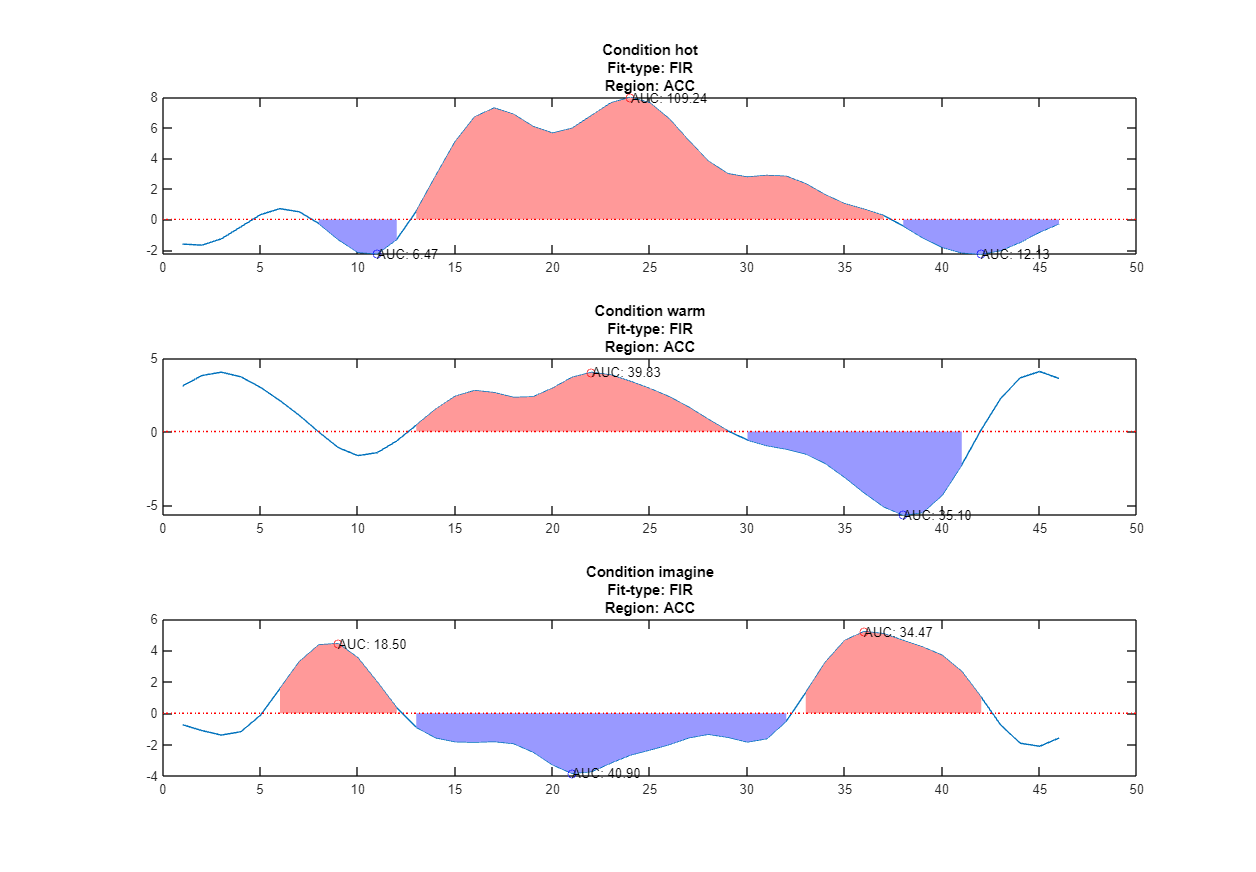

for s = 1:numel(subjects)

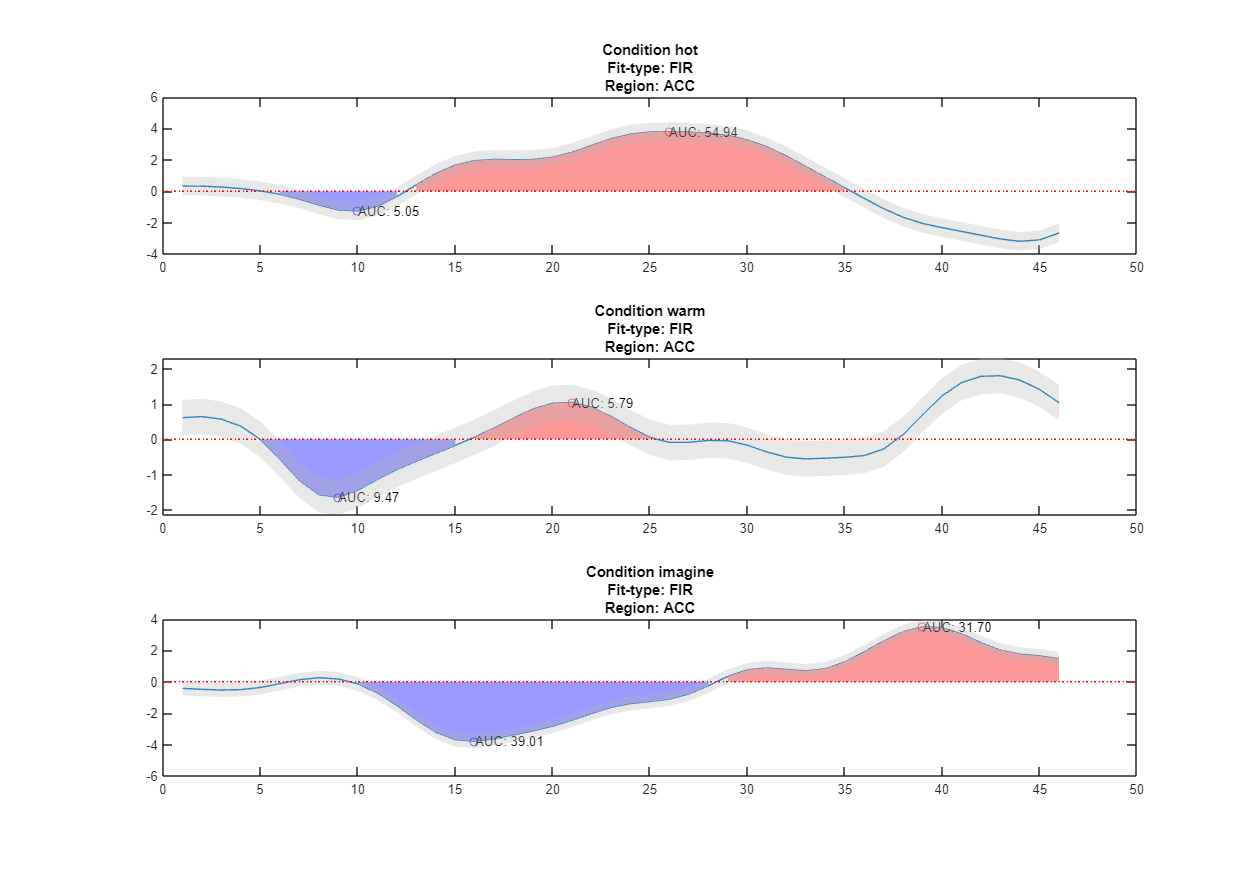

    disp(subjects{s});
    describeHRF(WASABIROIs_HRF{s});

end

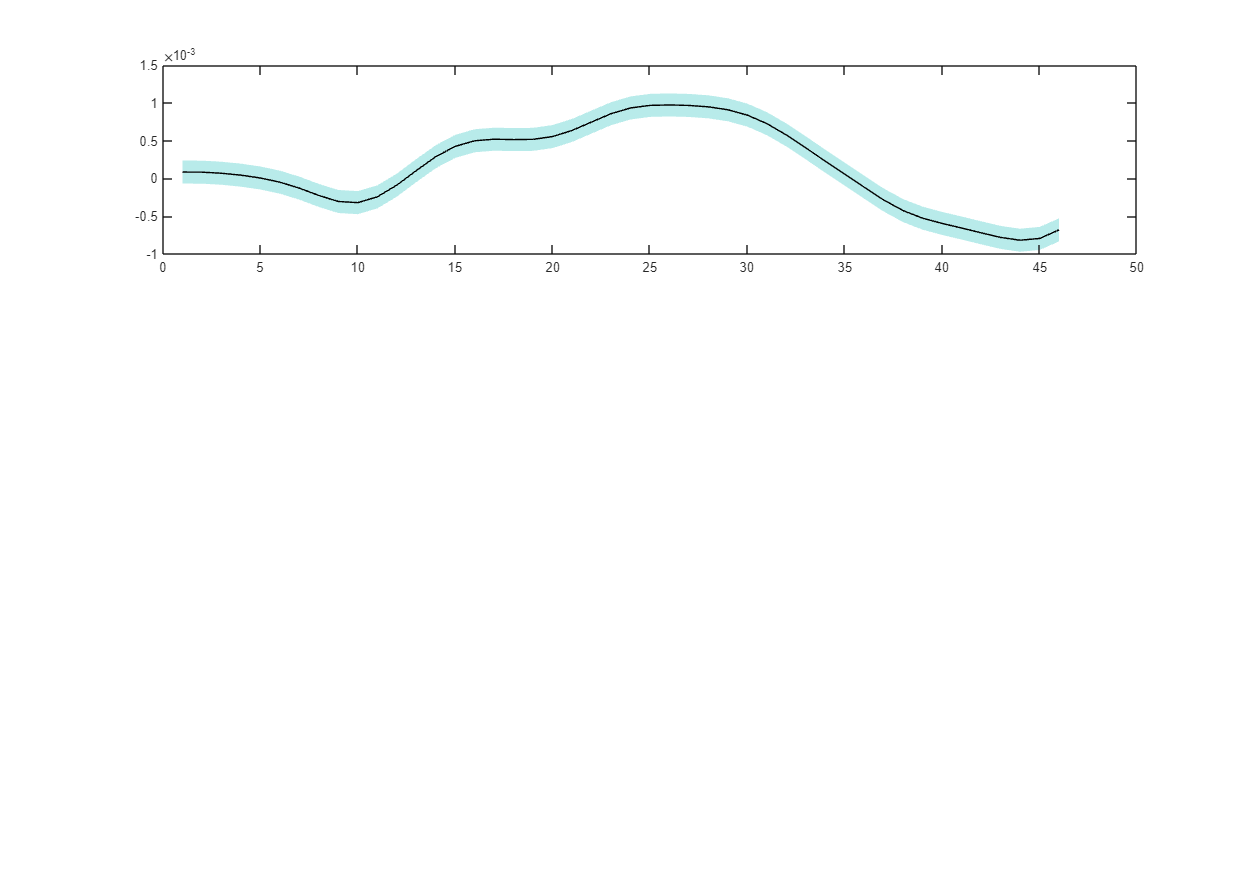

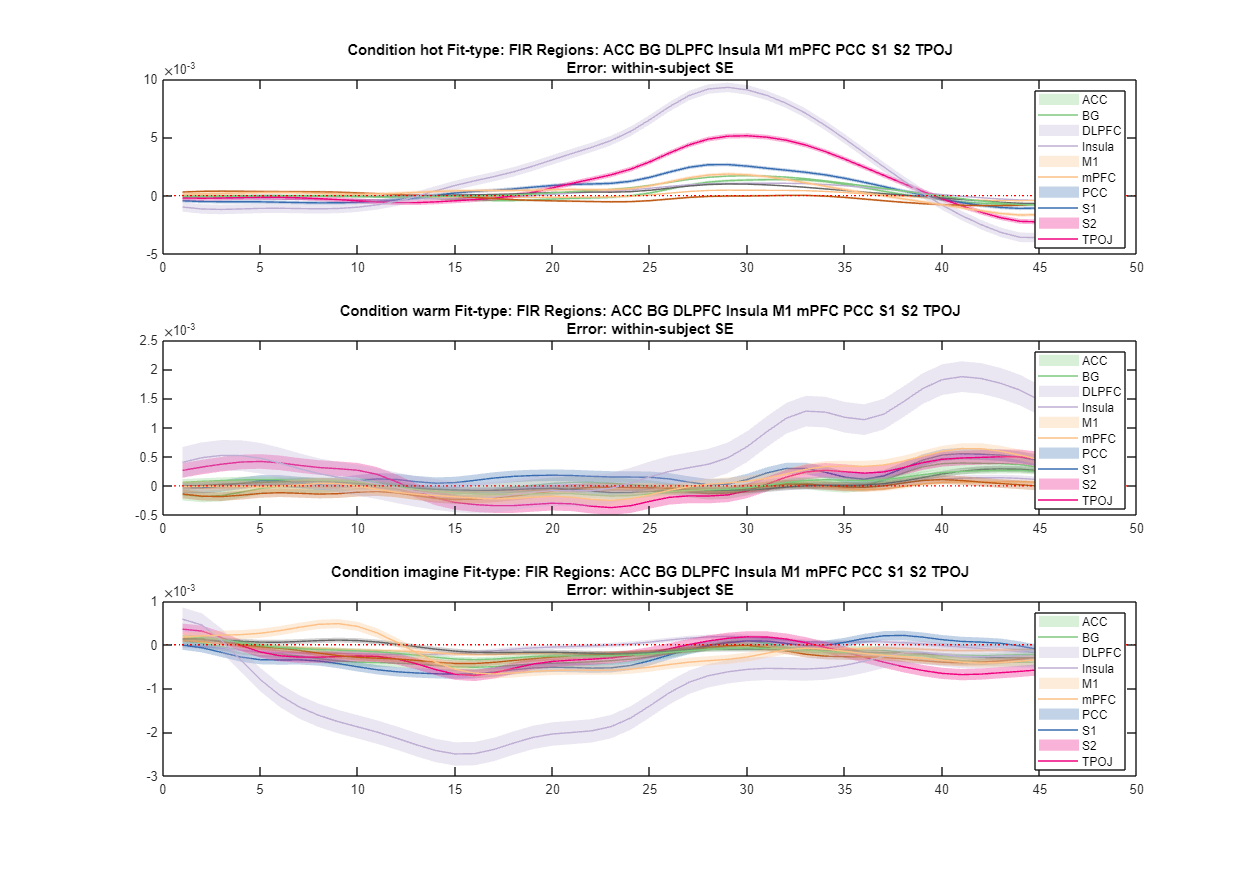

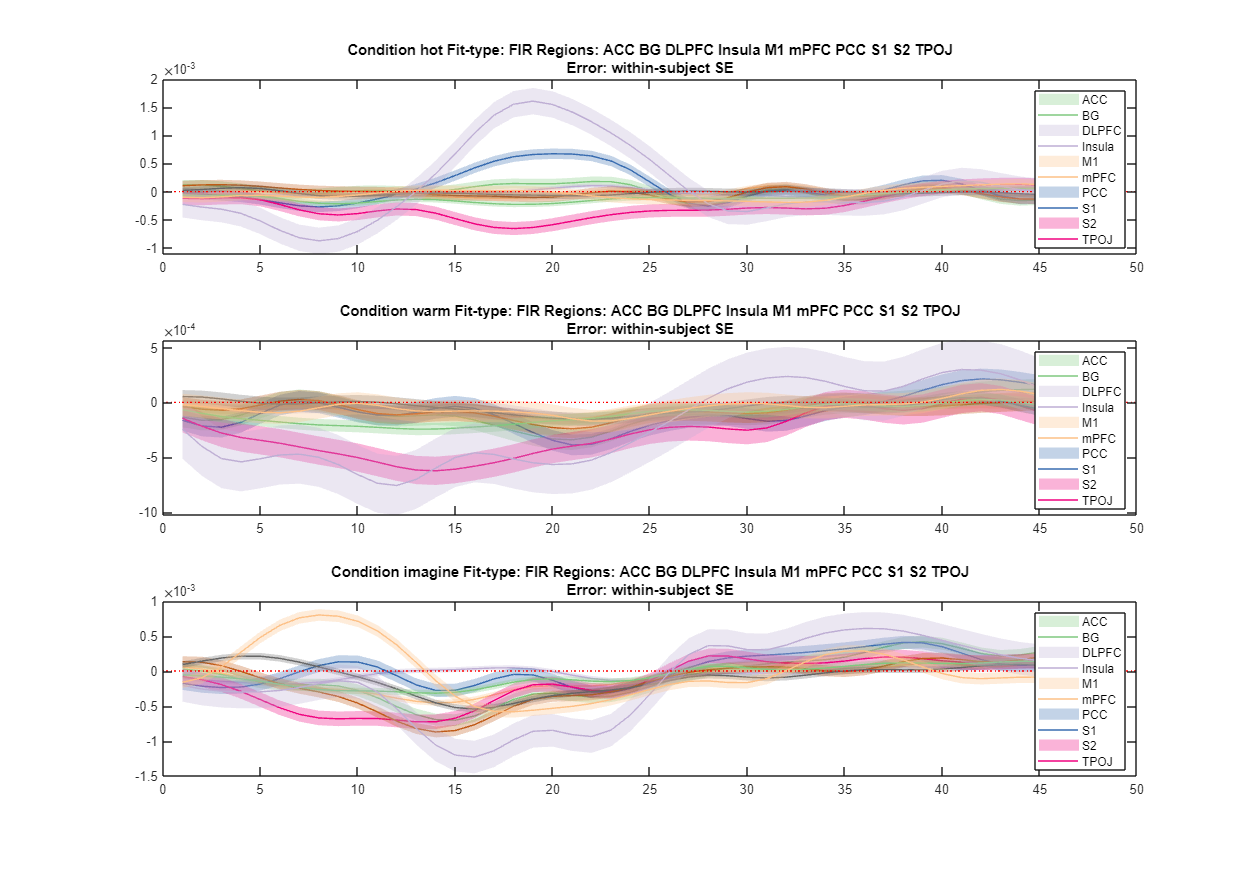

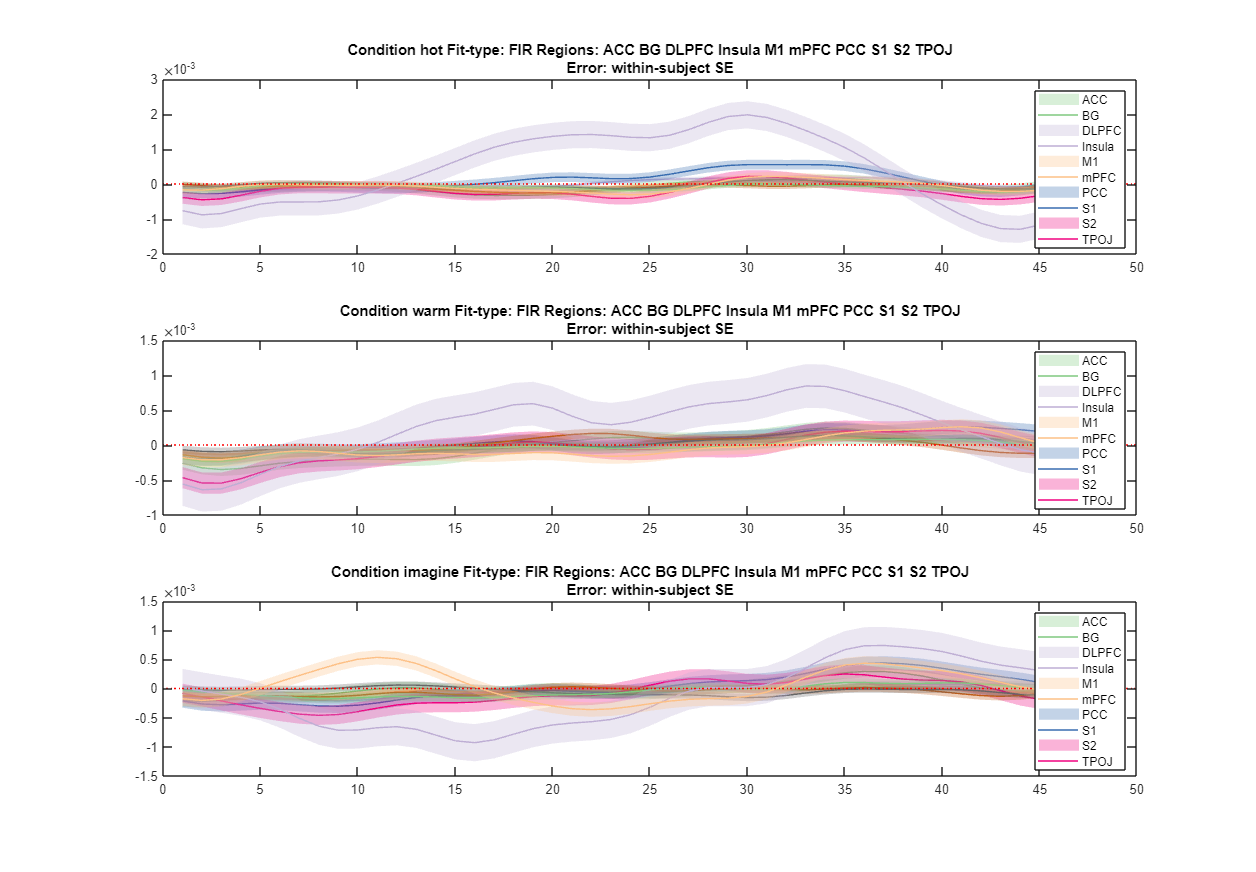

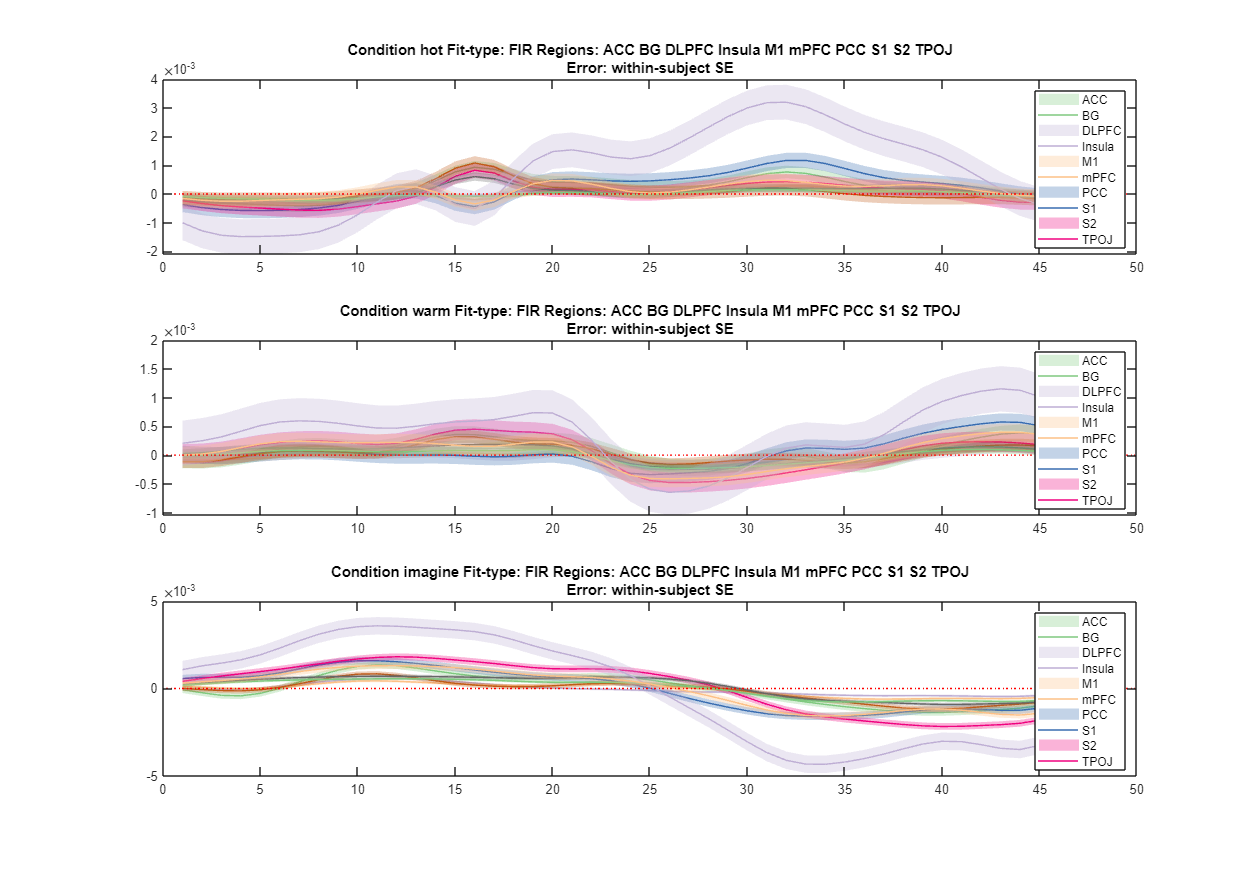

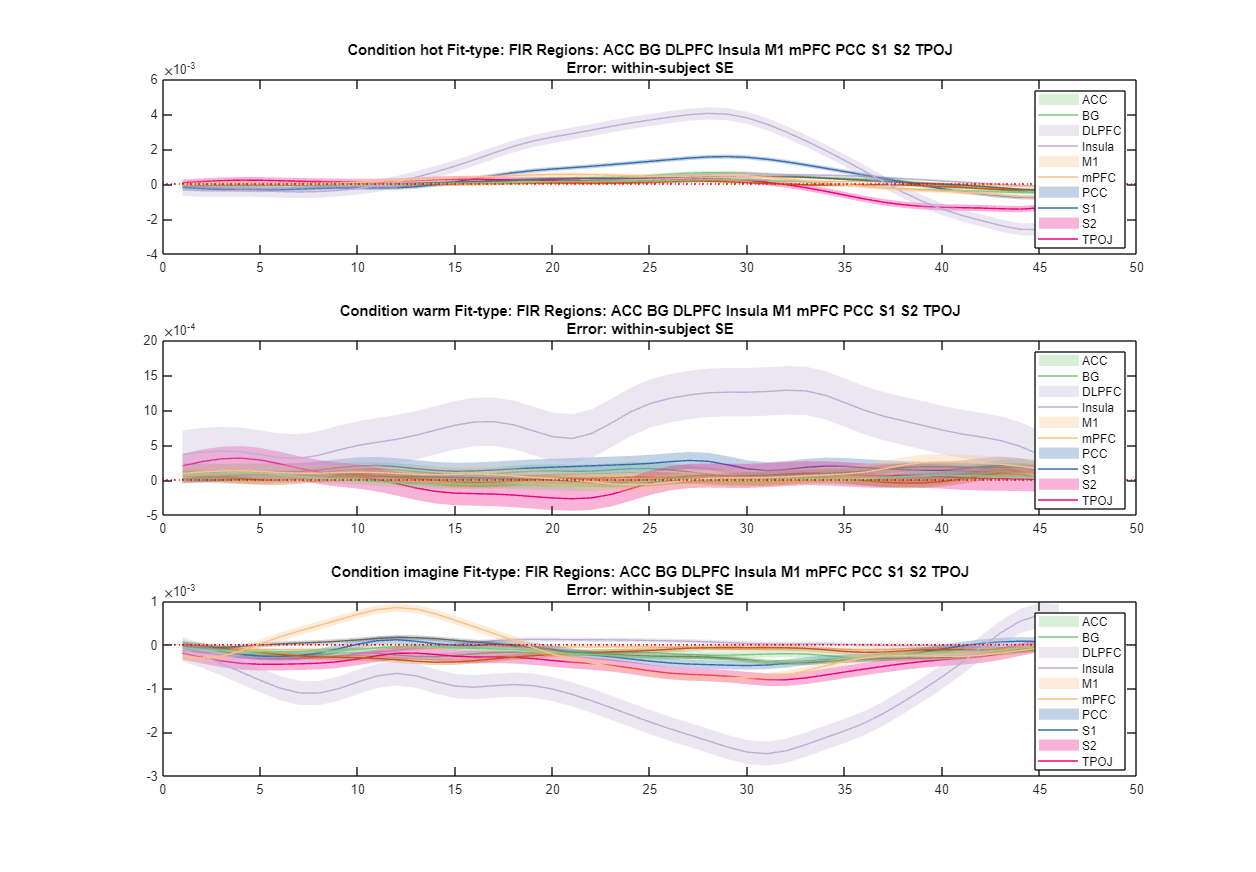

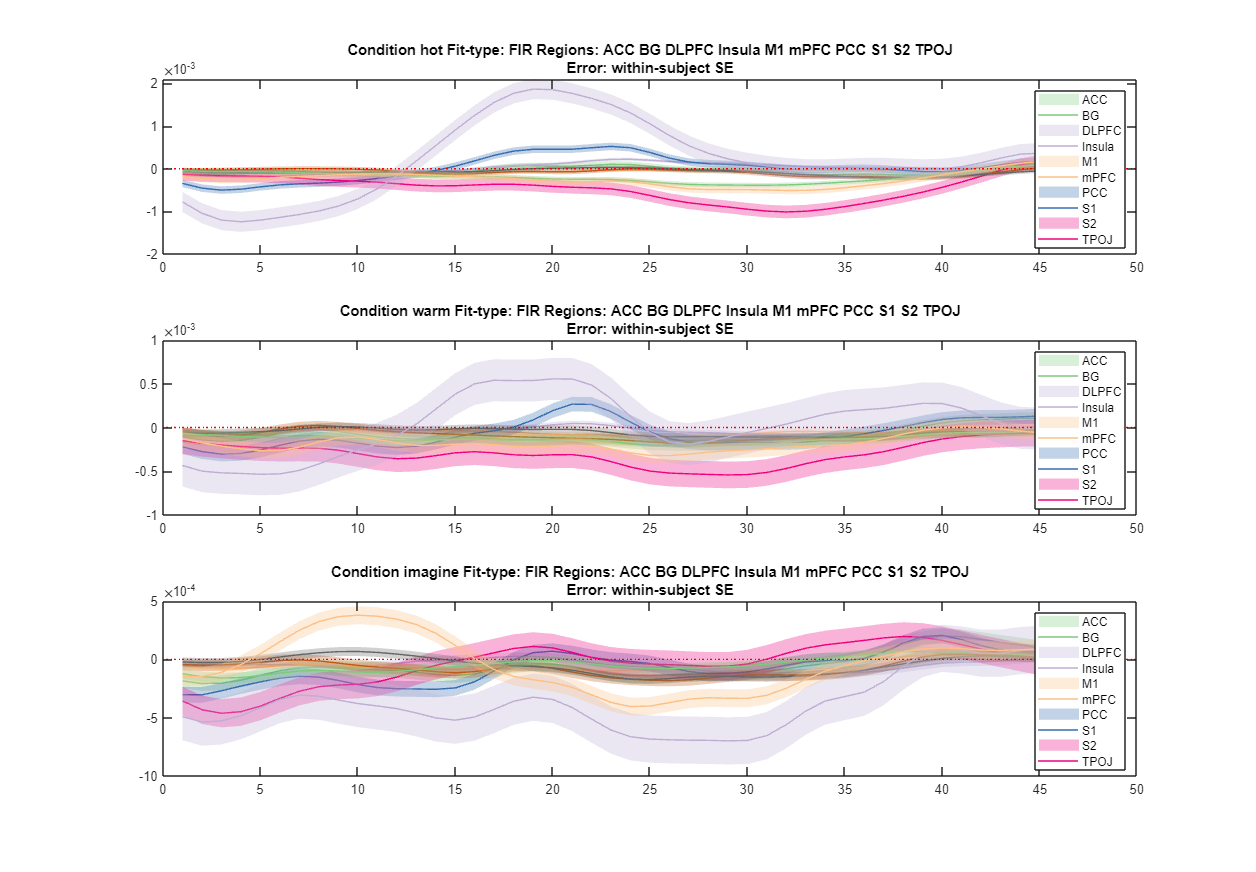

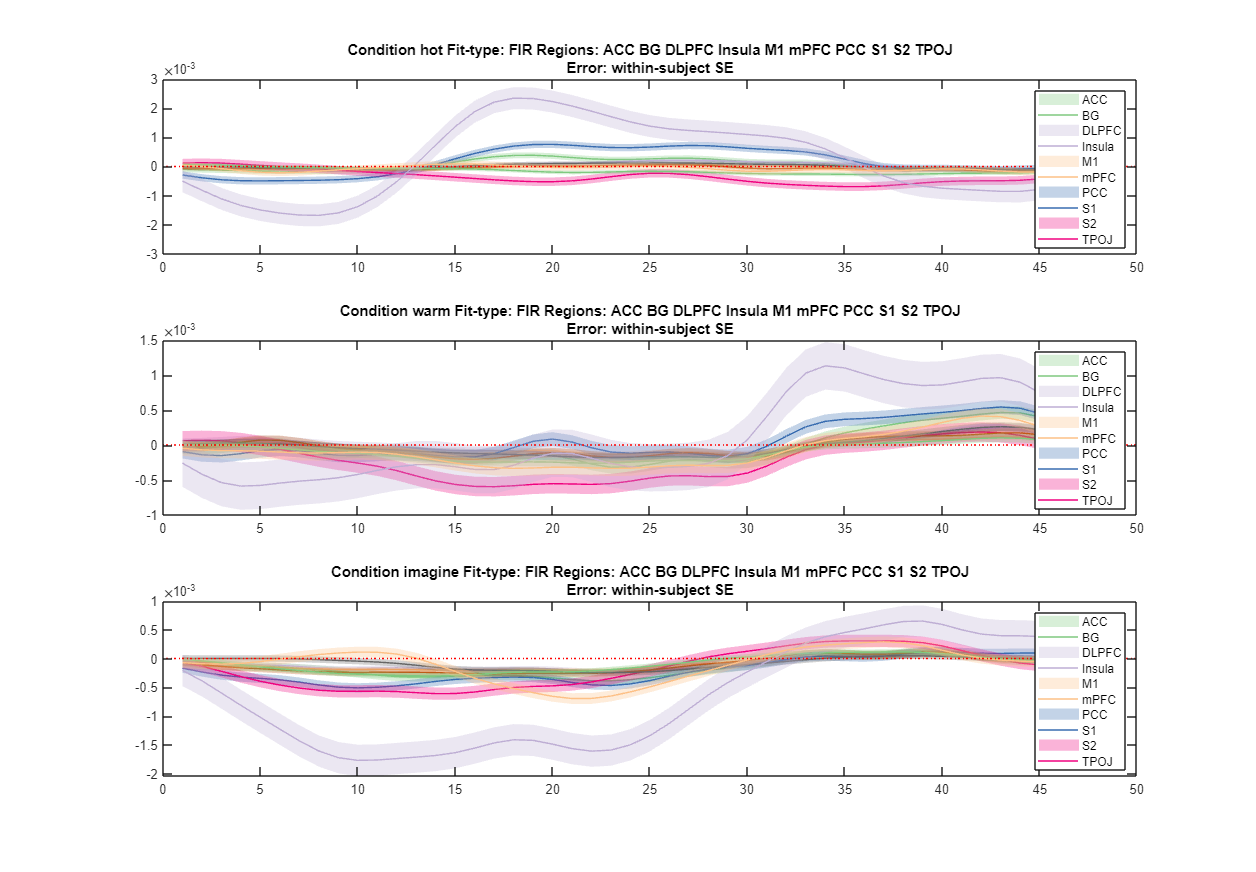

T = cell(1, length(subjects));
for s = 1:numel(subjects)


    disp(subjects{s});
    T{s}=generateHRFTable(WASABIROIs_HRF{s});

end

plotHRF(HRF_data{1}{6},'FIR',at,{'ACC'});

[m1, m2]=plotHRF(WASABIROIs_HRF{1}, 'FIR', at, {'ACC'});

The FIR fitted ACC features 2 phases of activity for the hot condition
Phase 1, spanning TRs 1  46 features 1 trough(s), (at TR(s) 15 and features an AUC of 94.4546 (voxel-normed: 0.024207).
Phase 2, spanning TRs 33  35 features 1 peak(s), (at TR(s) 34 and features an AUC of 2.8926 (voxel-normed: 0.00074132).
The FIR fitted BG features 1 phases of activity for the hot condition
Phase 1, spanning TRs 1  46 features 1 trough(s), (at TR(s) 15 and features an AUC of 106.3046 (voxel-normed: 0.01851).
The FIR fitted DLPFC features 1 phases of activity for the hot condition
Phase 1, spanning TRs 1  46 features 1 trough(s), (at TR(s) 17 and features an AUC of 64.6223 (voxel-normed: 0.0082796).
The FIR fitted Insula features 2 phases of activity for the hot condition
Phase 1, spanning TRs 1  41 features 1 trough(s), (at TR(s) 22 and features an AUC of 47.2845 (voxel-normed: 0.014846).
Phase 2, spanning TRs 42  46 features 1 peak(s), (at TR(s) 45 and features an AUC of 0.38235 (voxel-normed: 0.0

% for r=1:numel(WASABIROIs_HRF{1}.region)
%     for s = 1:numel(subjects)

      Type        Region       Condition     PhaseNum    PhaseSpan    Peaks    Troughs    TimeToPeak           AUC               AUC_VoxNormed    
    ________    __________    ___________    ________    _________    _____    _______    __________    __________________    ____________________
    {'FIR' }    {'ACC'   }    {'hot'    }       1         1    46       0         1       {[   15]}       94.4546338201928      0.0242067231727813
    {'FIR' }    {'ACC'   }    {'hot'    }       2        33    35       1         0       {[   34]}        2.8926245213479    0.000741318431918991
    {'CHRF'}    {'ACC'   }    {'hot'    }       1         1    30       

Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat


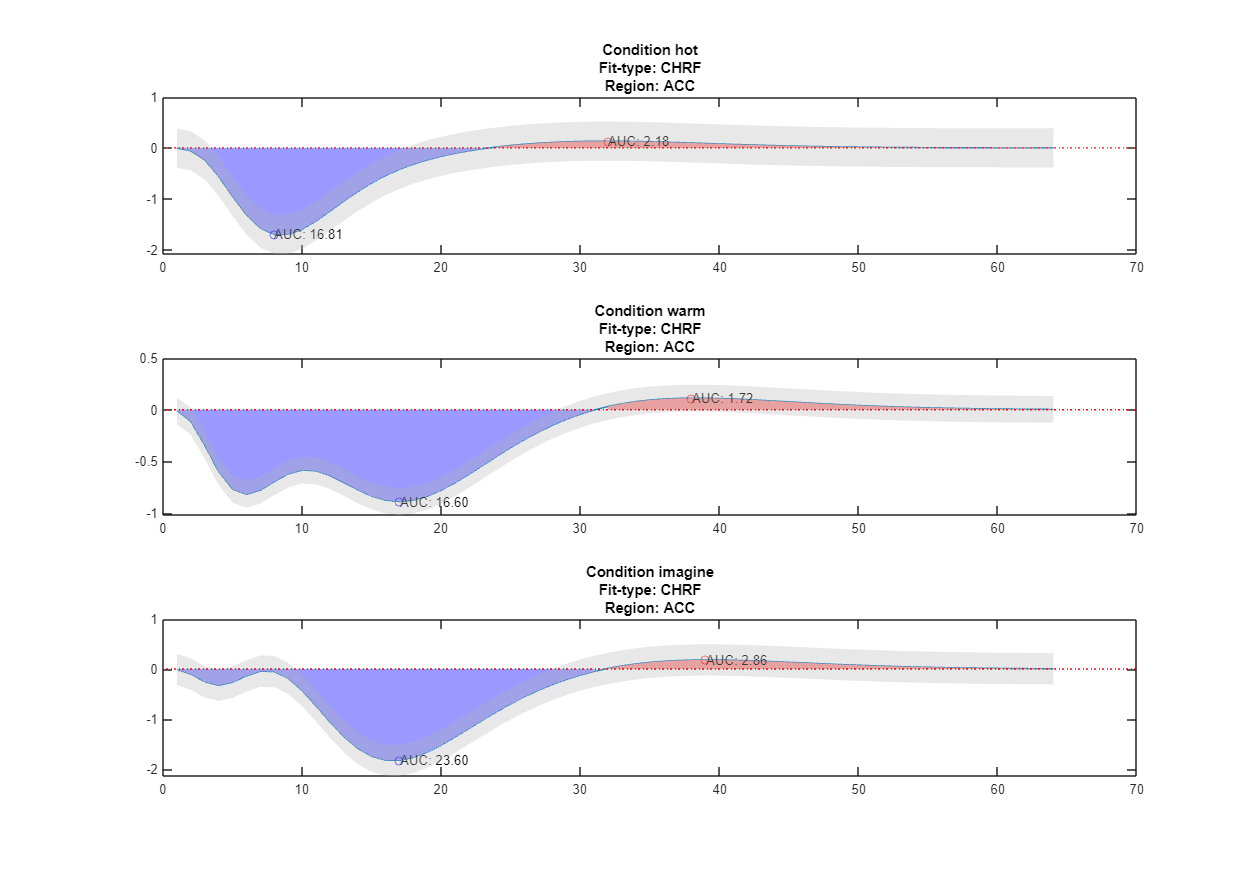

Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat


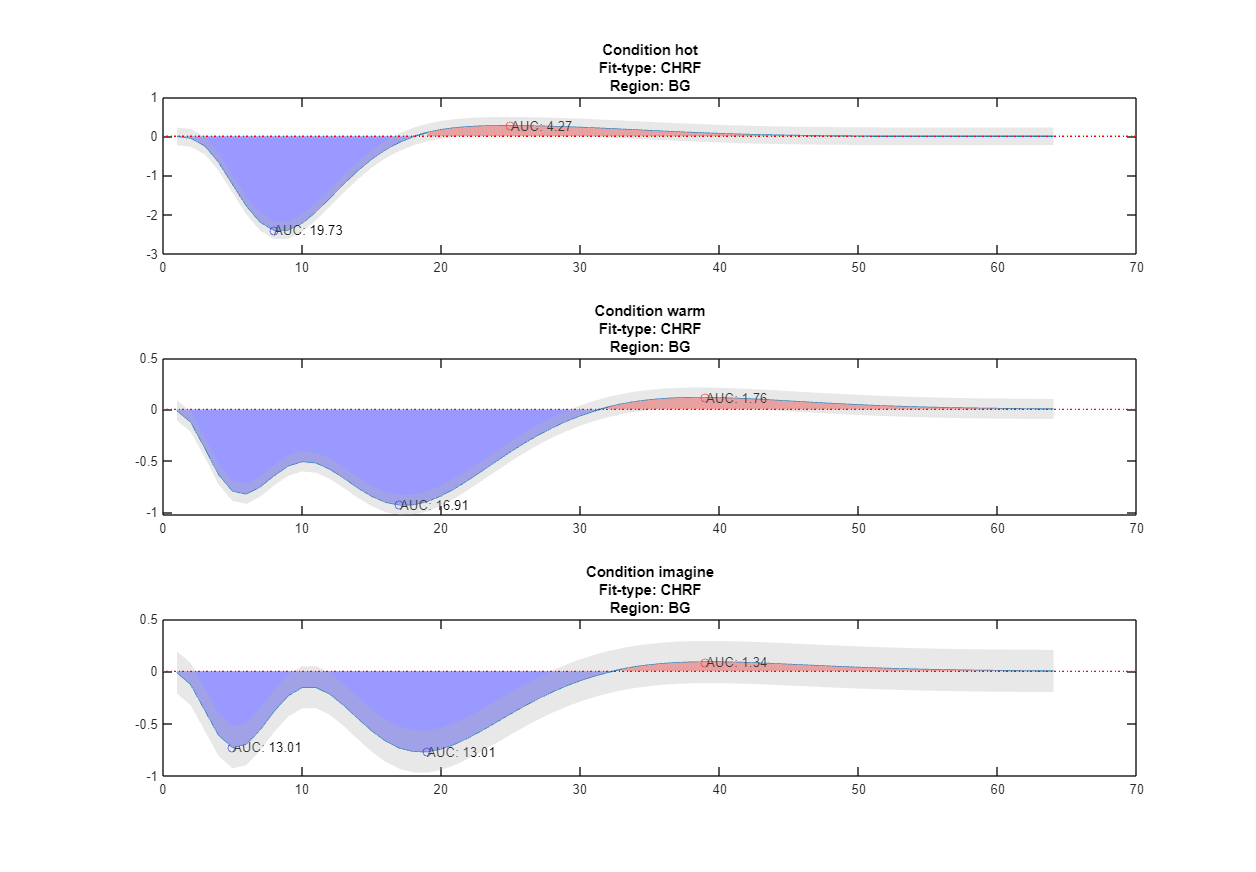

Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat


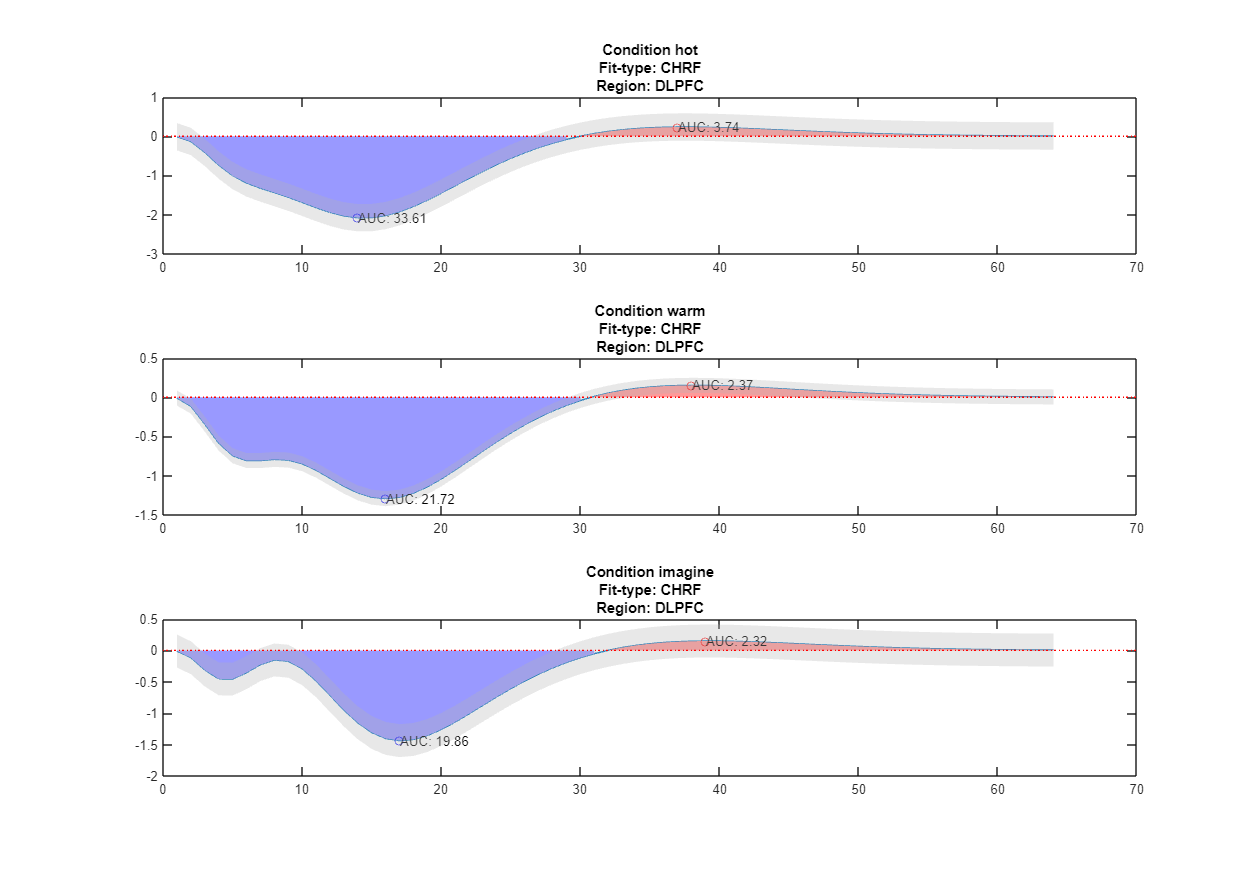

Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat


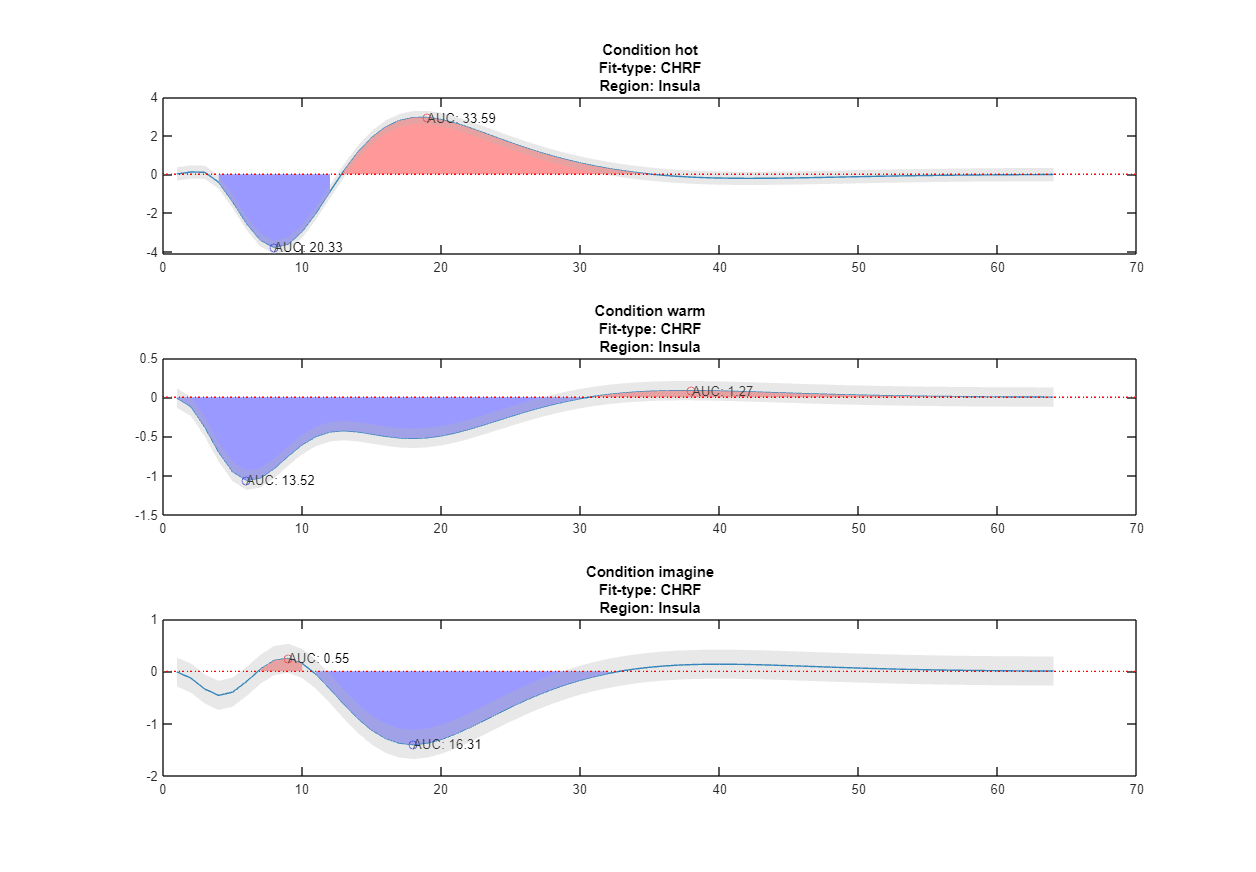

Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat


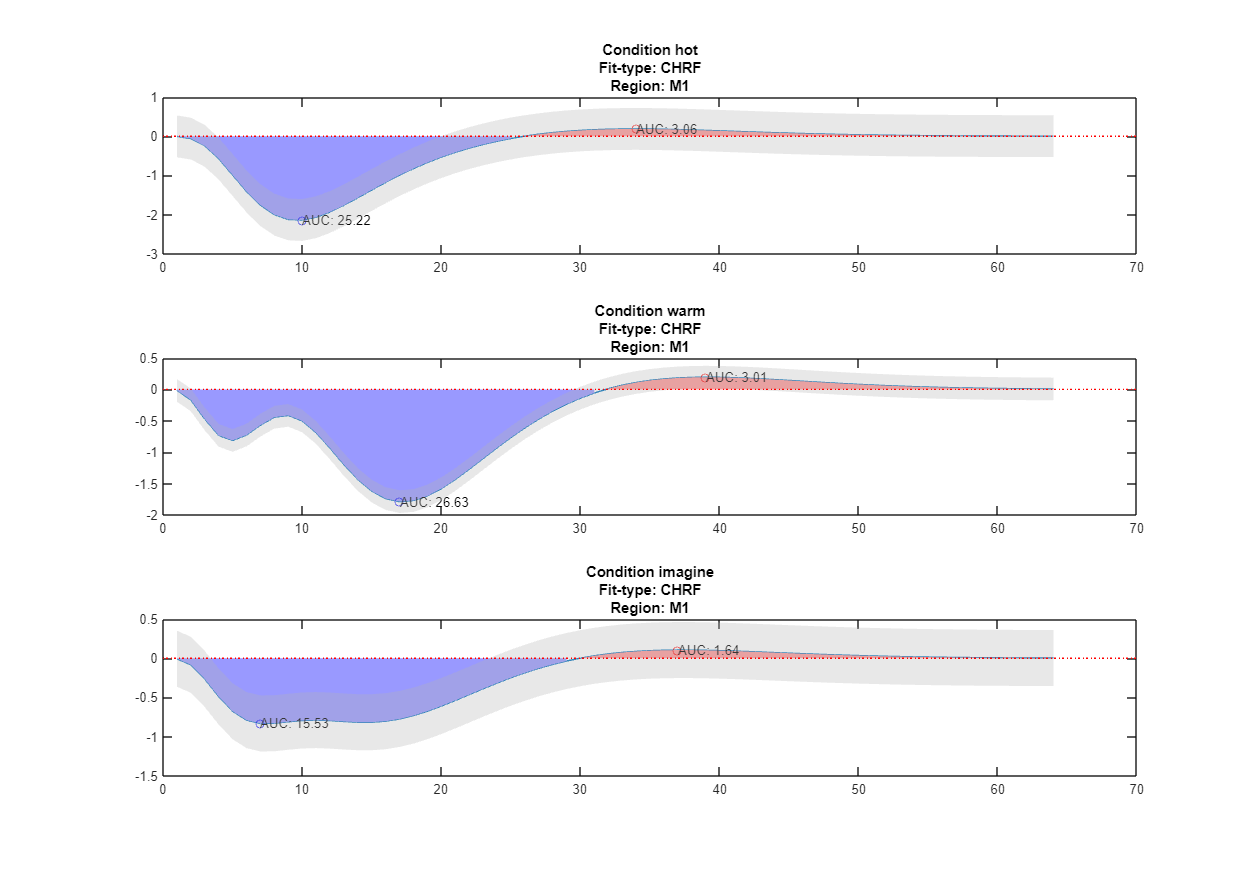

Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat


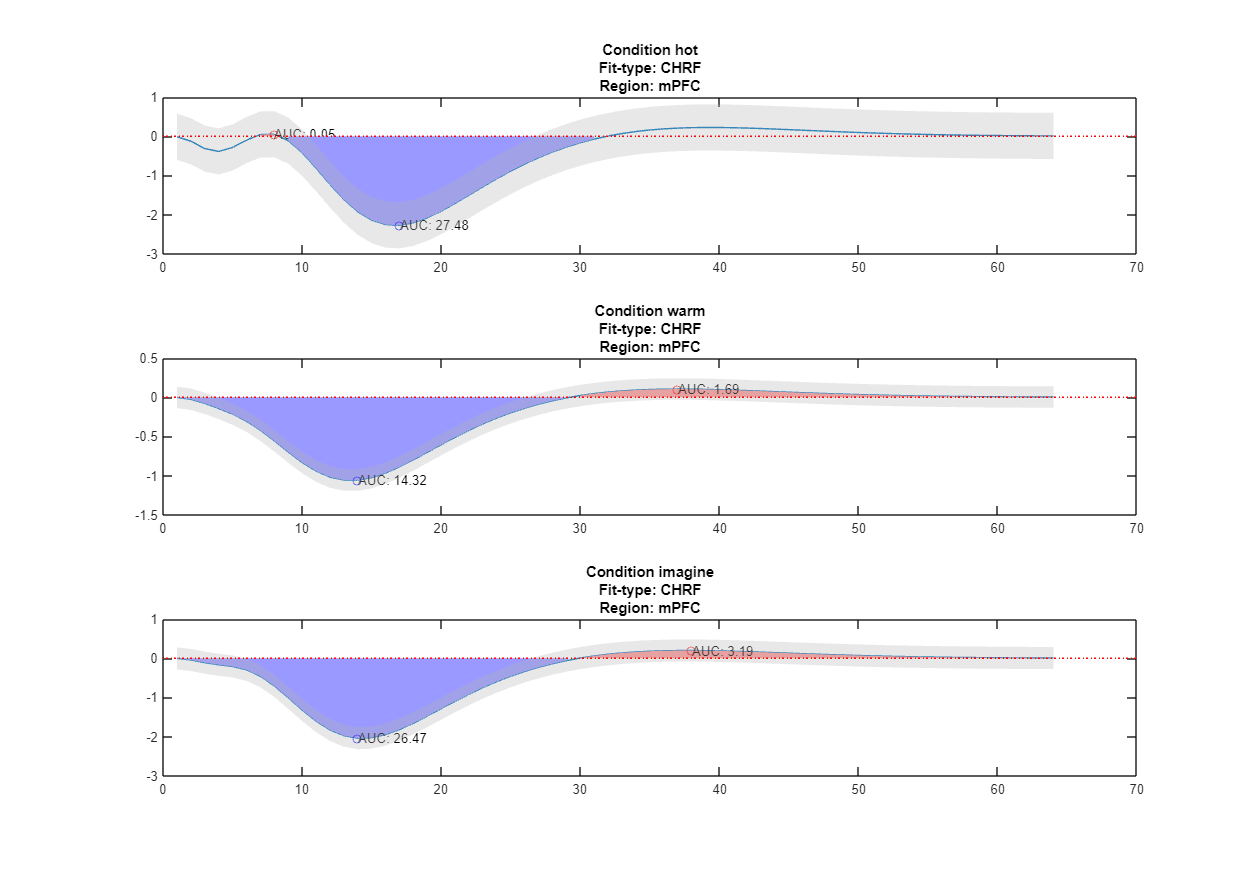

Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat


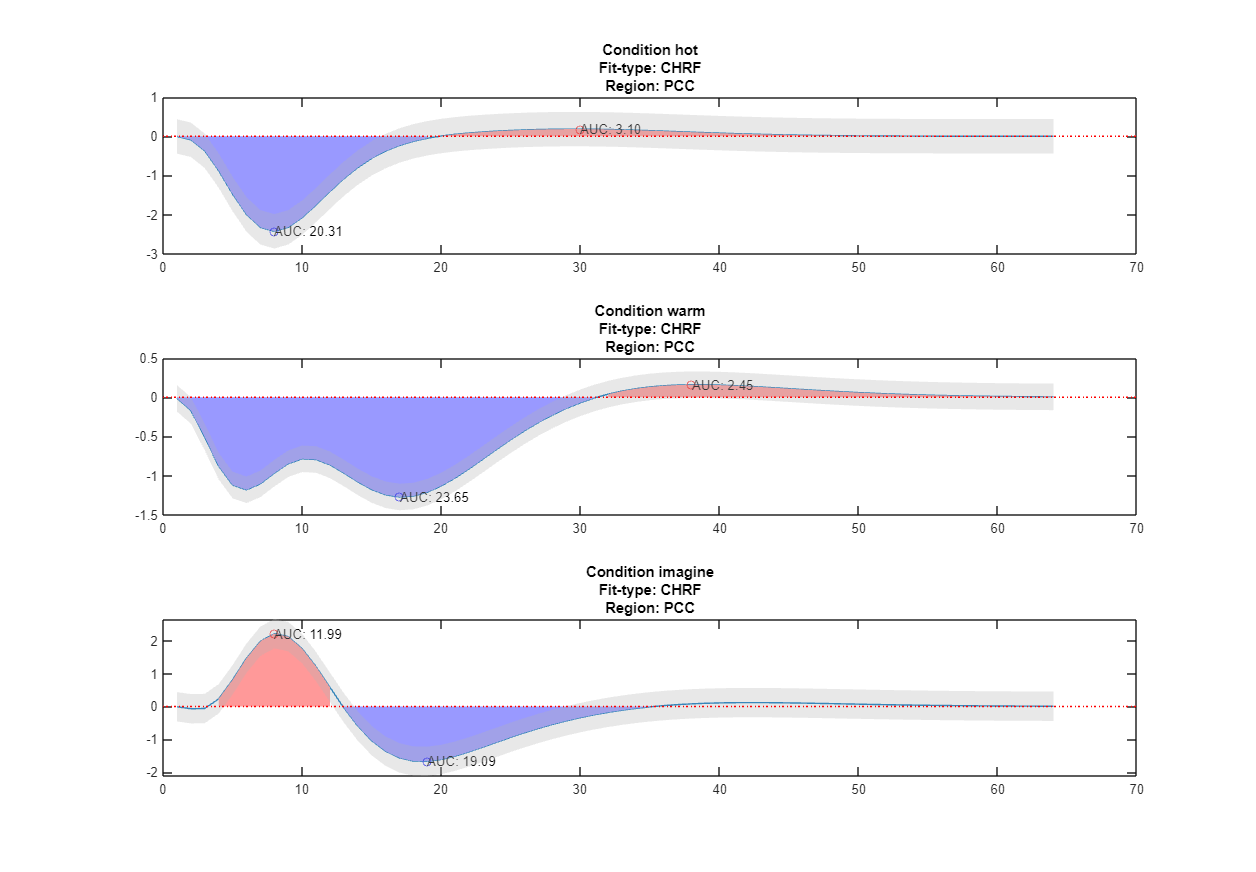

Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat


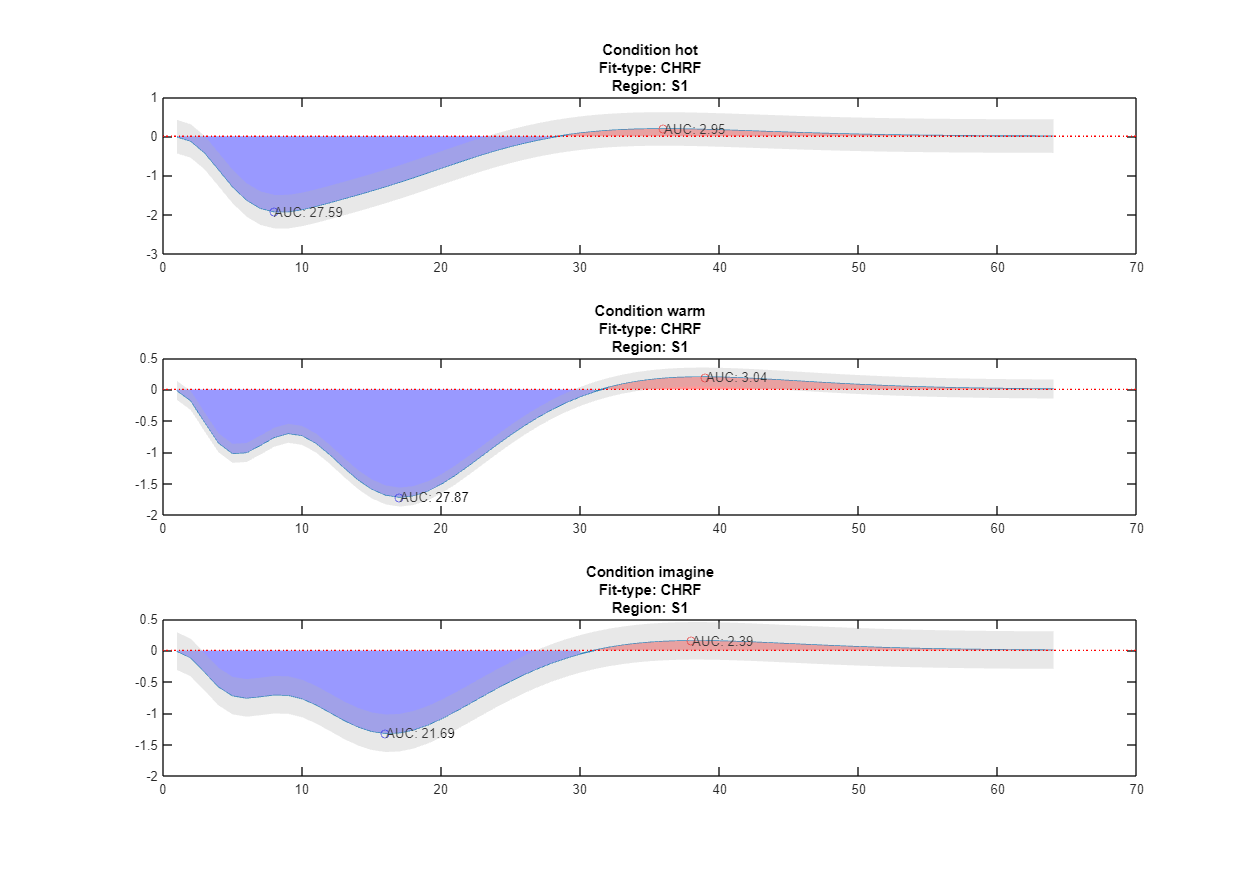

Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat


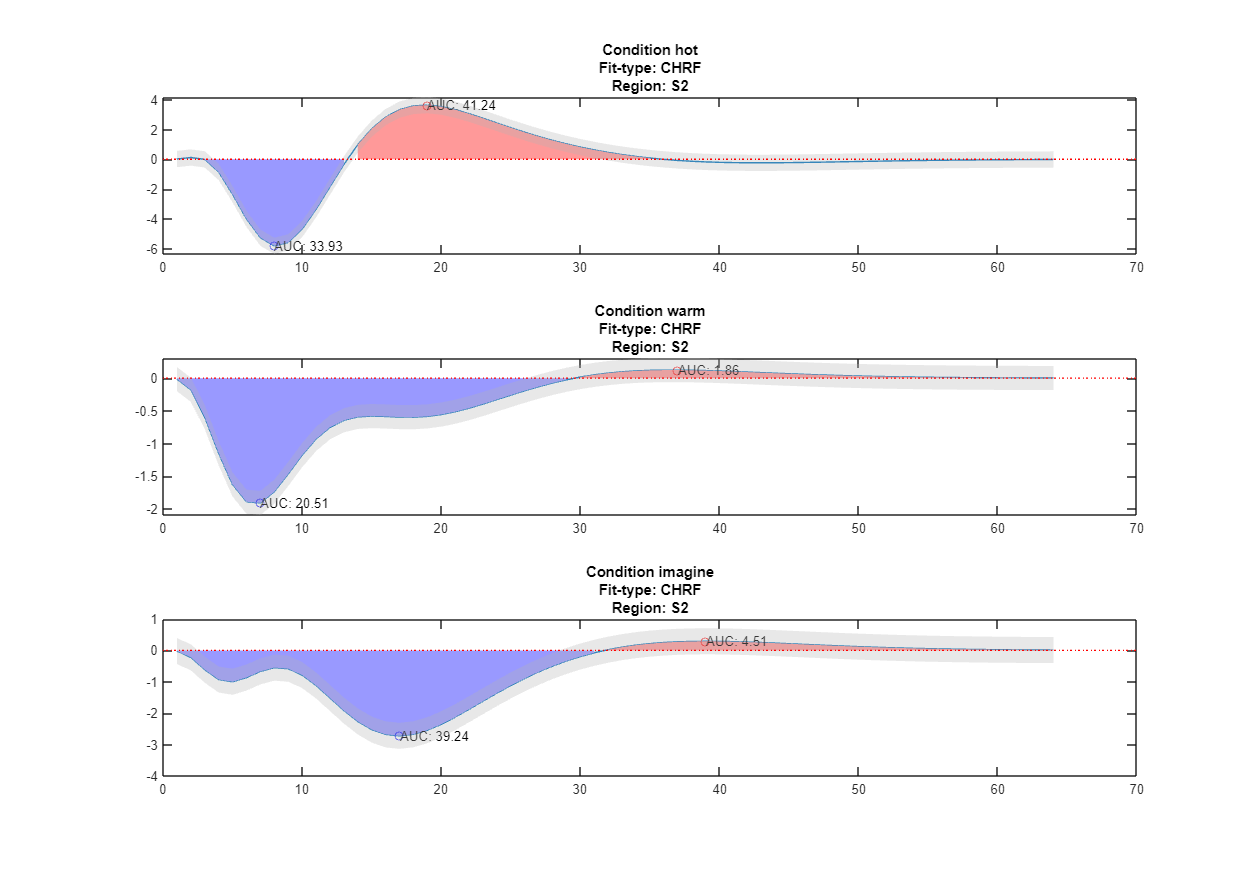

Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat


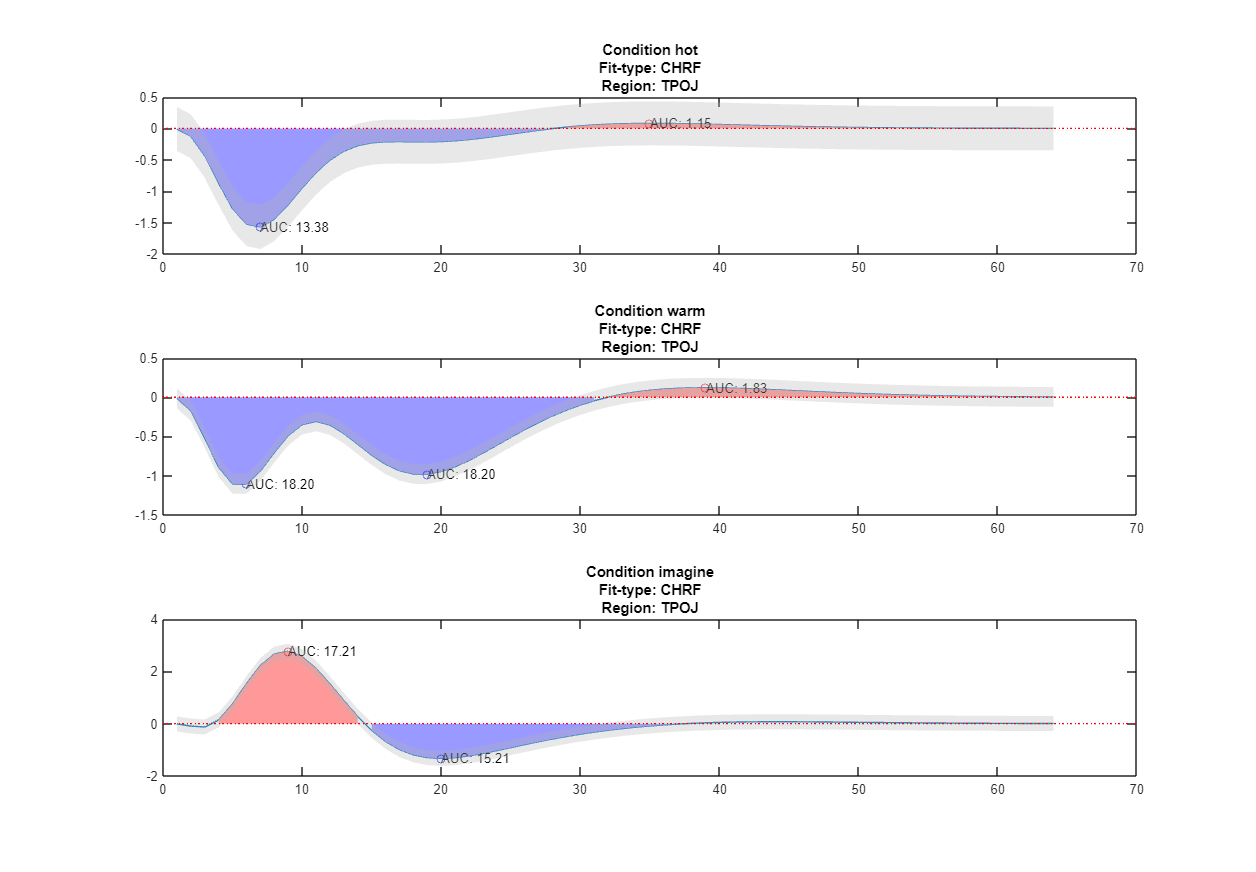

%         % subplot(3, numel(subjects), s)
%         plotHRF(WASABIROIs_HRF{s}, 'FIR', WASABIROIs_HRF{s}.region{r});
%     end
% end
for s = 1:numel(subjects)

Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat


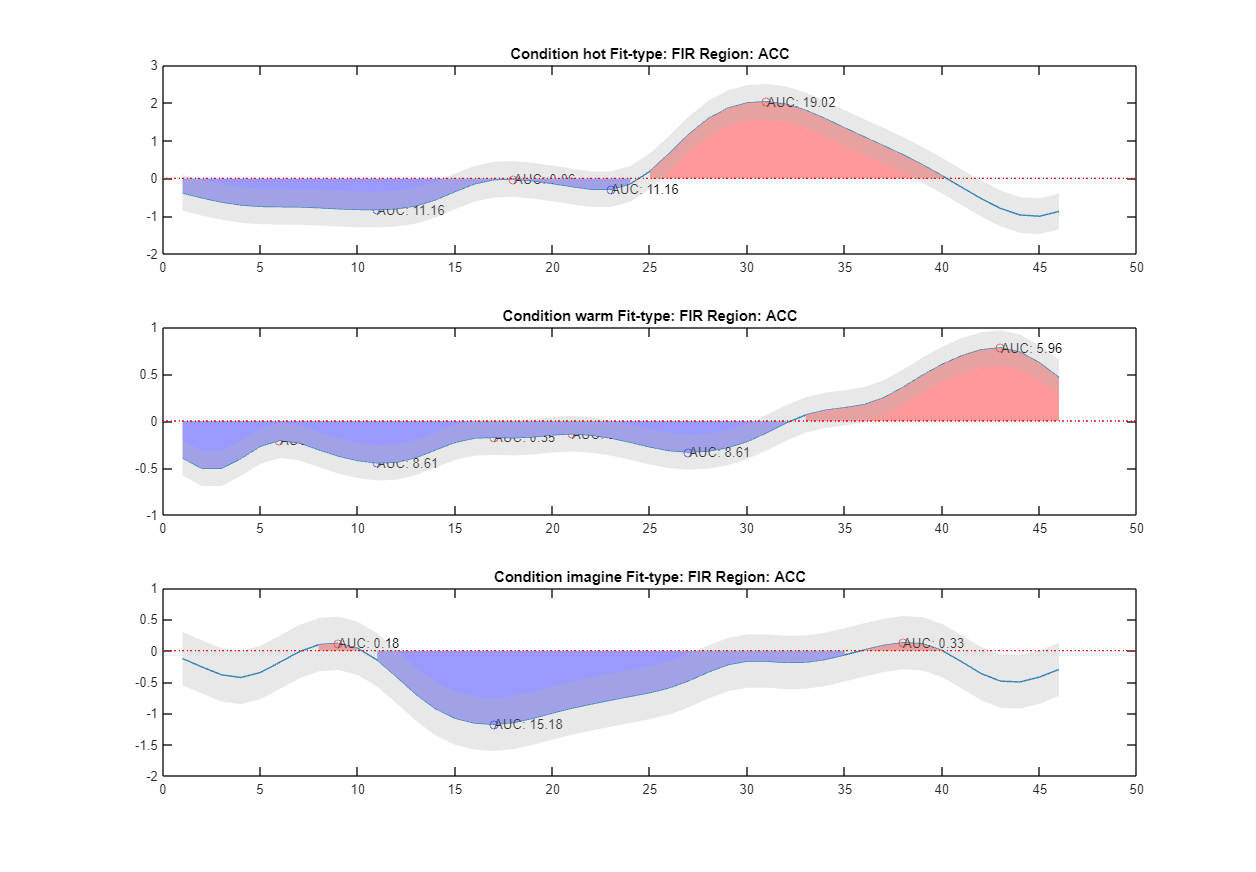

Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat


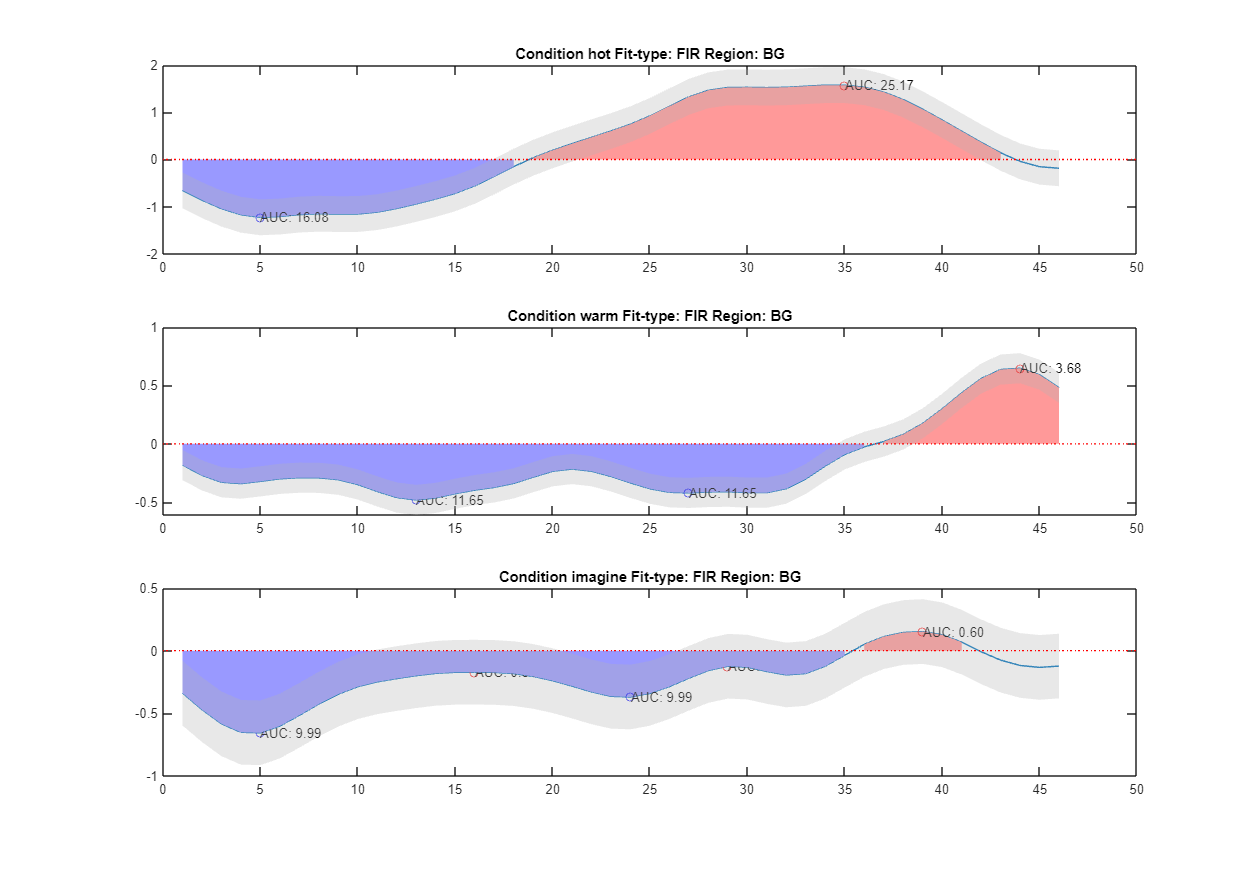

Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat


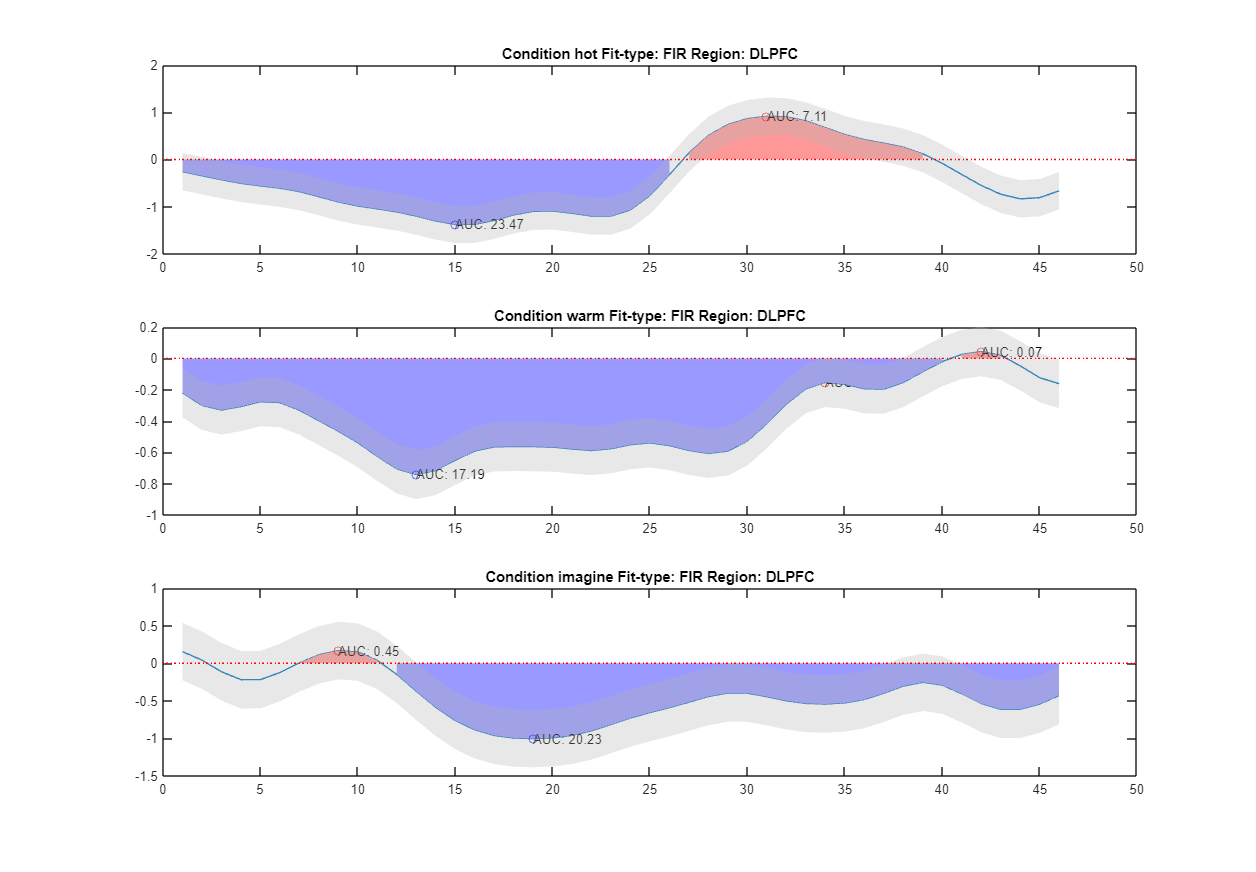

Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat


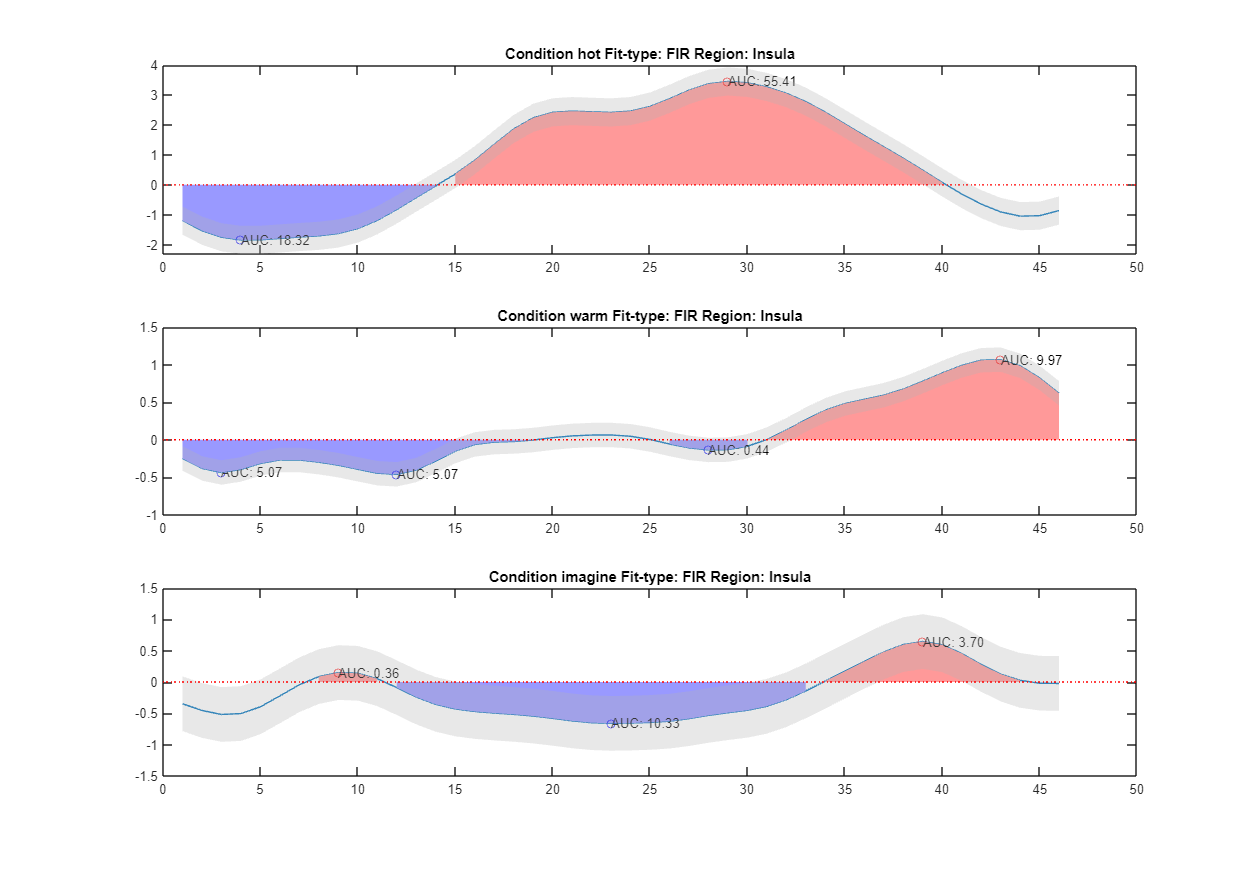

Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat


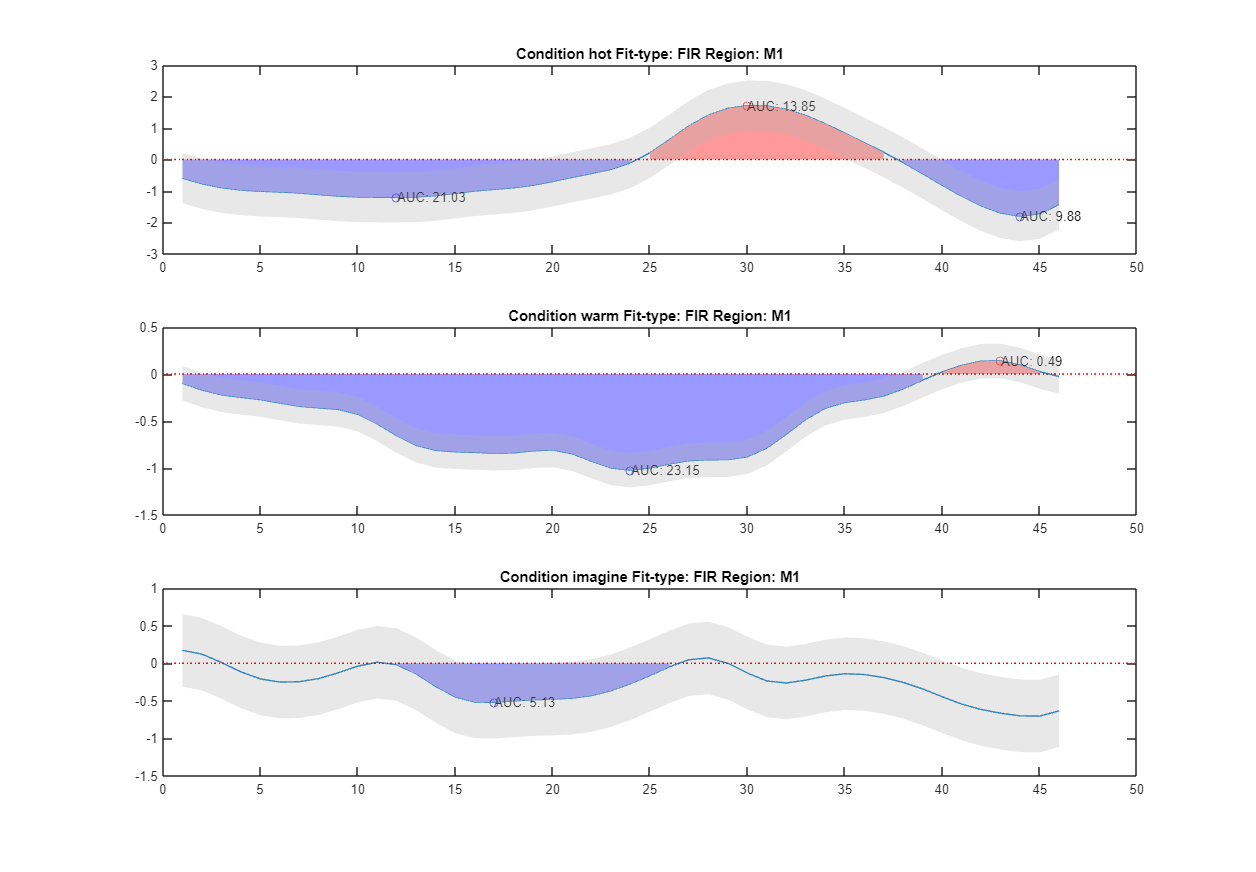

Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat


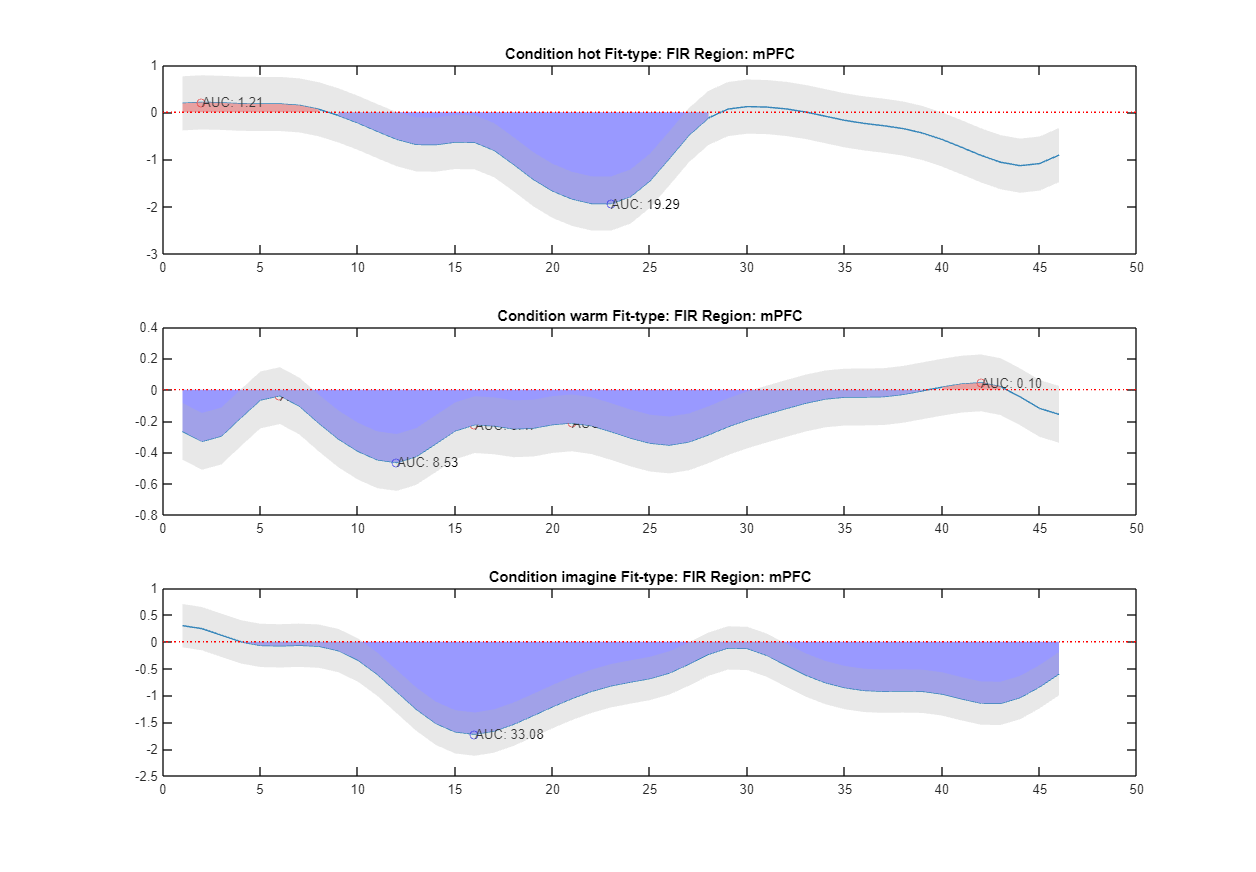

Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat


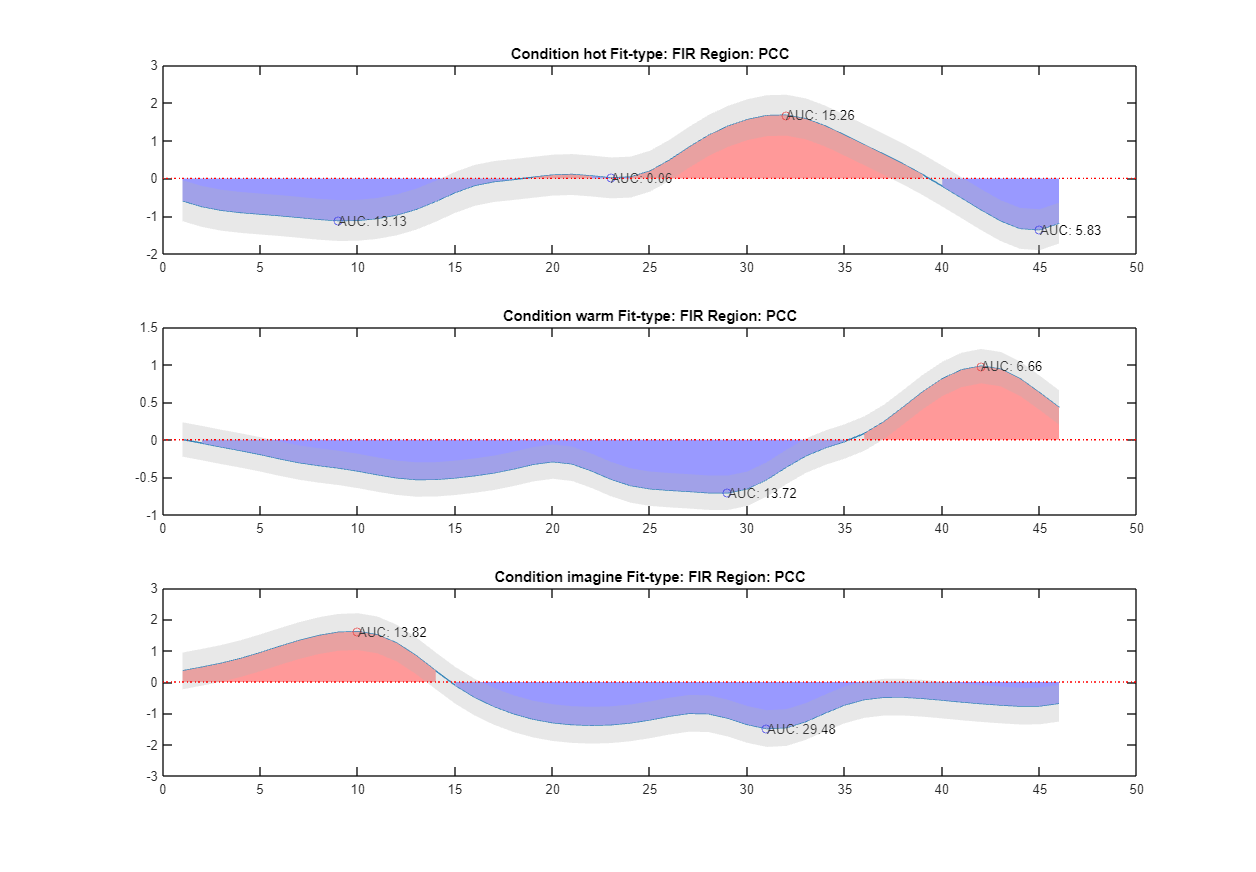

Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat


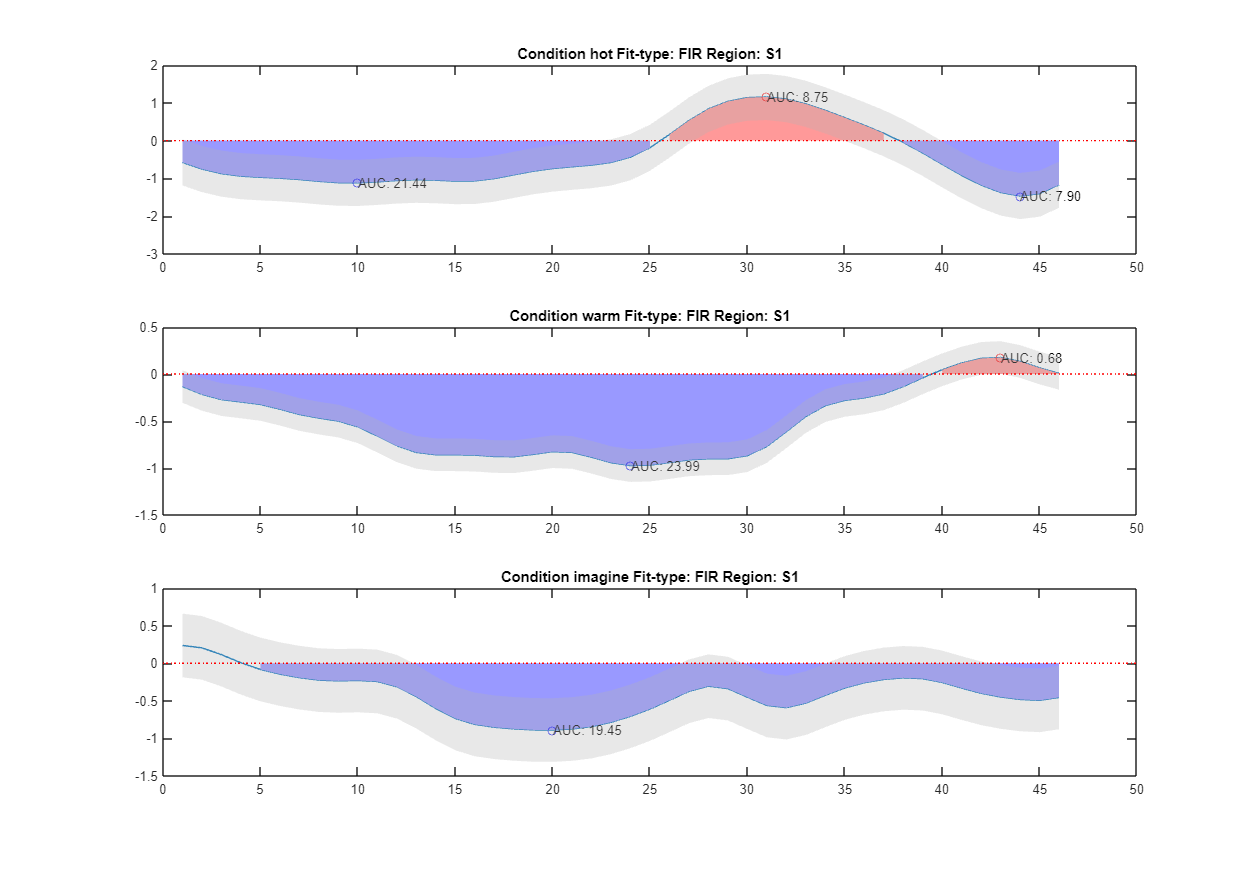

Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat


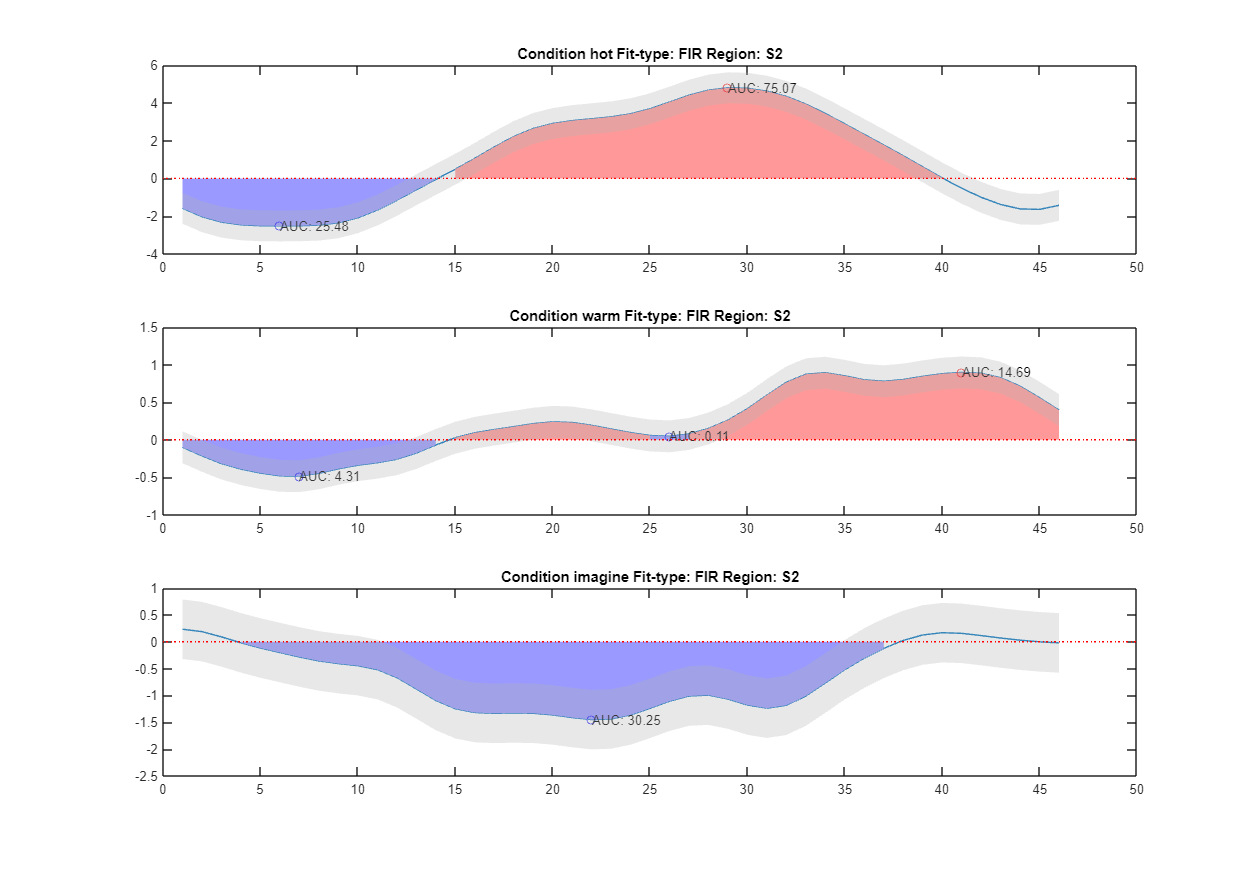

Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat


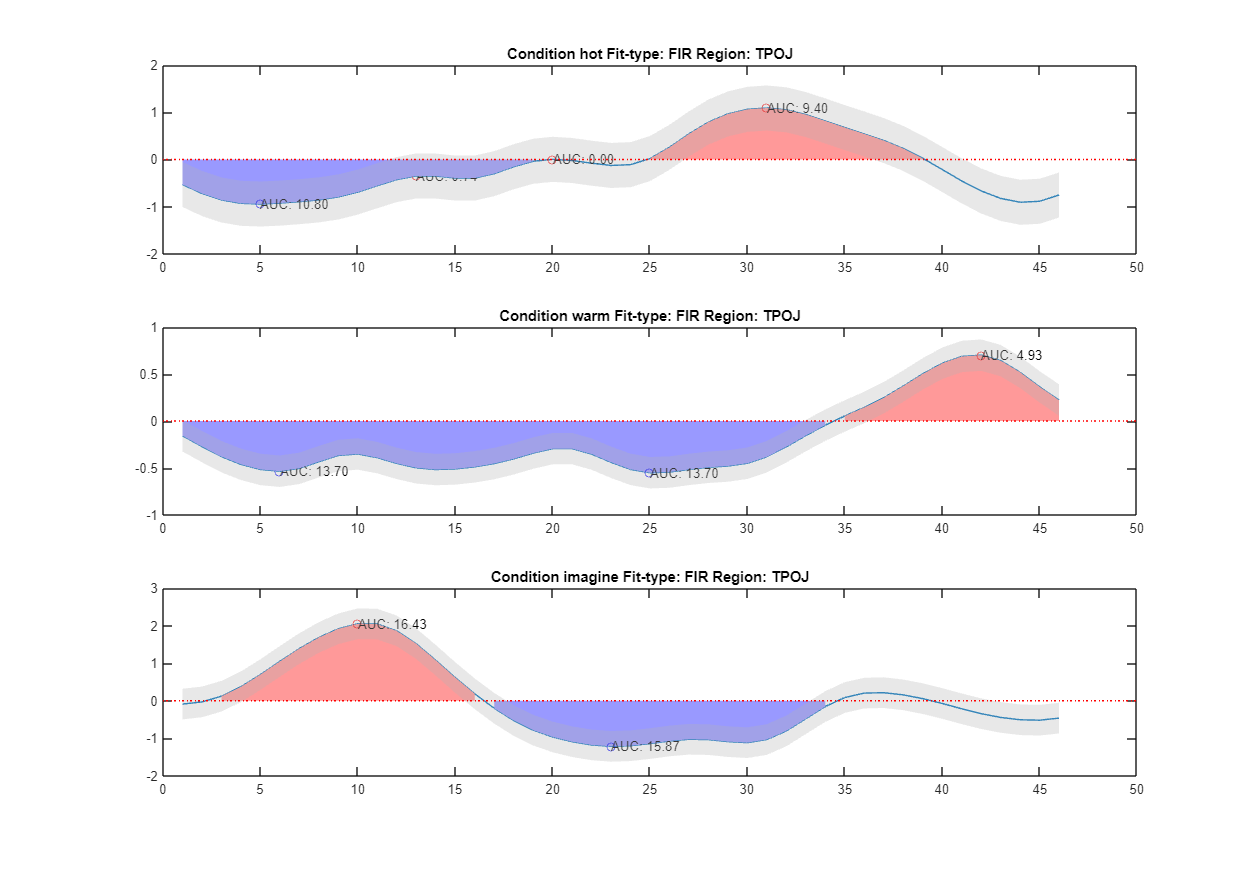

    plotHRF(WASABIROIs_HRF{s}, 'FIR', at);
end

## Step 9: Third-Level Analyses: Averaging Across Subjects

`_________________________________________________________________________`

Here's how I might do it:

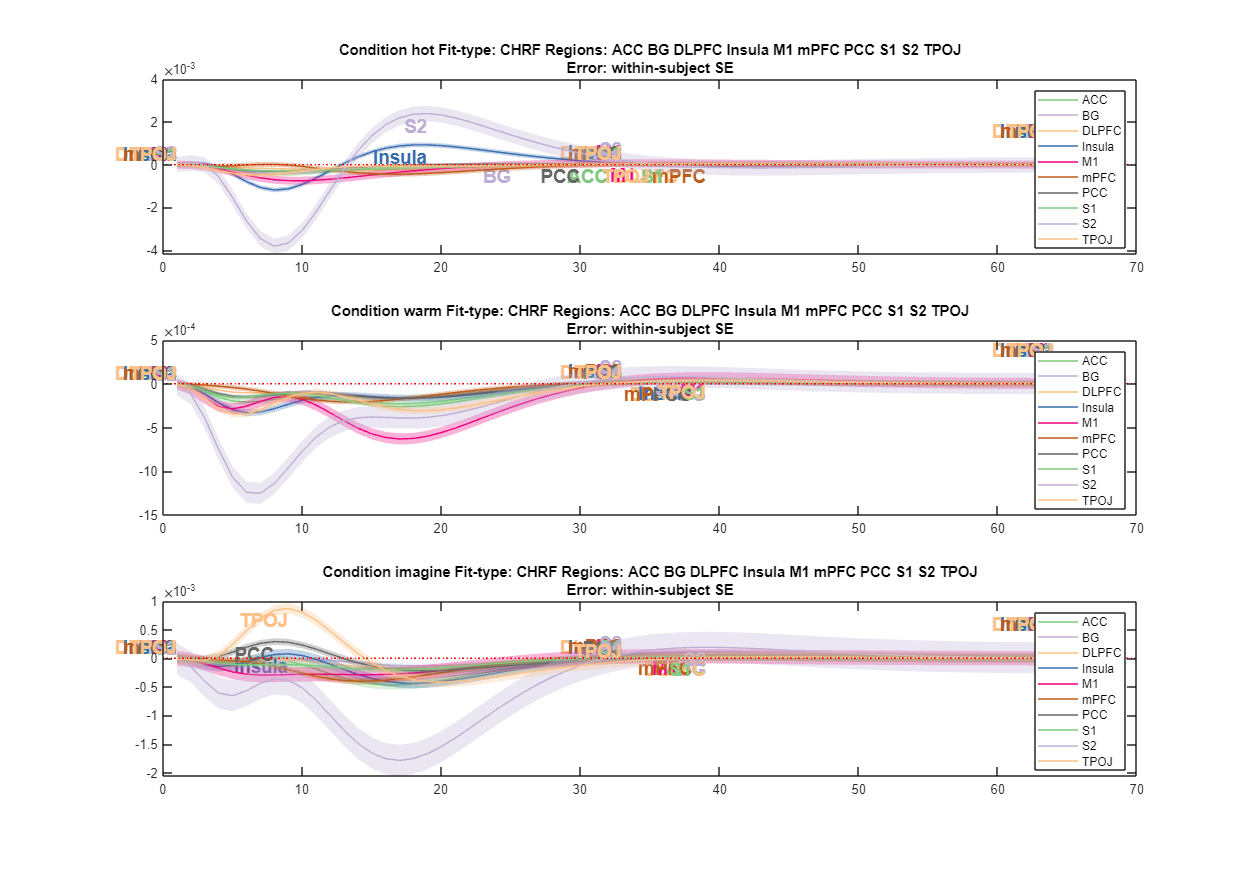

WASABIROIs_HRF_3=HRF_avg(WASABIROIs_HRF, at);

describeHRF(WASABIROIs_HRF_3);

T_3=generateHRFTable(WASABIROIs_HRF_3);

for r=1:numel(WASABIROIs_HRF_3.region)
    % subplot(3, numel(subjects), s)
    plotHRF(WASABIROIs_HRF_3, 'CHRF', WASABIROIs_HRF_3.region{r});
end

for r=1:numel(WASABIROIs_HRF_3.region)
    % subplot(3, numel(subjects), s)
    plotHRF(WASABIROIs_HRF_3, 'FIR', WASABIROIs_HRF_3.region{r});
end

plotHRF(WASABIROIs_HRF_3, 'CHRF', at);

plotHRF(WASABIROIs_HRF_3, 'FIR', at);

%% Append bodysite information to each HRF structure
load('C:\Users\Admin\Documents\GitHub\canlab\CanlabCore\CanlabCore\HRF_Est_Toolbox2\EstHRF_inAtlas\avgHRF_example.mat')


for r=1:numel(WASABIROIs_HRF_3.region)
    % All regions relative to one another
    plotHRF(WASABIROIs_HRF_3, 'FIR', at); % This function reveals some alarming things about our estimation by region.

    % Plot summary stats of a single region
    plotHRF_summarystats(WASABIROIs_HRF_3, 'FIR', WASABIROIs_HRF_3.region{r});
    
    % Plot all regions in one graph
    plotHRF_summarystats(WASABIROIs_HRF_3, 'FIR');

end





## Helper Functions

function jobTable = processJobTable(infoTable, taskString, targetStrings, HRF_PARAMS, PREPROC_PARAMS)
    % Create a logical index to filter rows containing the specified task
    logicalIndex = contains(infoTable.ScanFile, taskString);

    % Use the logical index to subset the table
    filteredInfoTable = infoTable(logicalIndex, :);

    outdir='/dartfs-hpc/rc/lab/C/CANlab/labdata/data/WASABI/derivatives/estHRF/';

    % Loop through the rows of the filtered table
    for row = 1:size(filteredInfoTable, 1)
        % Process each target string
        condition_names={};
        % Initialize cell arrays for onset and duration for the current row
        onsRow = {};
        durRow = {};
        for c = 1:numel(targetStrings)
            % Find columns that contain the current target string
            matchingCols = find(endsWith(filteredInfoTable.Properties.VariableNames, targetStrings{c}));
            
            % Process each matching column
            for col = matchingCols
                % Extract and process the data if the cell is not empty
                if ~isempty(filteredInfoTable{row, col})
                    dict = filteredInfoTable{row, col}{1};
                    if isa(dict, 'containers.Map') && isKey(dict, 'onset') && isKey(dict, 'duration')
                        onsRow(end+1) = dict('onset');
                        durRow(end+1) = dict('duration');
                        condition_names{end+1}=filteredInfoTable.Properties.VariableNames{col};
                    end
                end
            end
        end

        % Perform further processing and populate the table
        try
            % Here, implement the logic to use onsRow, durRow, HRF_PARAMS, and PREPROC_PARAMS
            % to populate the filteredInfoTable. For example:
            % filteredInfoTable.Condition{row} = generateConditionTS(...);
            % ...
            
            % NOTE: Replace '...' with actual processing steps and assignments.
            filteredInfoTable.Condition{row}=generateConditionTS(height(filteredInfoTable.noise_model{row}), condition_names, onsRow, durRow);
            % Store the onset and duration cell arrays for the current row in ons and dur
            filteredInfoTable.ons{row} = onsRow;
            filteredInfoTable.dur{row} = durRow;
    
            PREPROC_PARAMS.R=filteredInfoTable.noise_model{row};
            
            filteredInfoTable.PREPROC_PARAMS{row}=PREPROC_PARAMS;
    
            HRF_PARAMS.Condition=filteredInfoTable.Condition{row};
            HRF_PARAMS.CondNames=condition_names;
            filteredInfoTable.HRF_PARAMS{row}=HRF_PARAMS;
    
            filteredInfoTable.outfile{row}=strrep(fullfile(outdir, filteredInfoTable.Subject{row}, filteredInfoTable.Session{row}, '', strrep(filteredInfoTable.ScanFile{row}, '.nii.gz', '')), '\', '/');
        catch
            warning(['Error processing row ', num2str(row), ': ', filteredInfoTable.ScanFile{row}]);
        end
    end

    % Return the processed table
    jobTable = filteredInfoTable;
end